# Lesson III.3:   Discrete Linear Dynamics

**Analyzing and computing iterates of a linear map.   **Iterating a linear map defined by an $n\times n$ matrix $A$,

        (III.3.1a)        ${\bf x}_{\ell+1}=A{\bf x}_\ell$,

produces, starting from an initial vector ${\bf x}_0$, a sequence of vectors ${\bf x}_0,{\bf x}_1,{\bf x}_2,\dots$  Some sequences generated by iterating several linear maps are shown below.   Evidently, there are diverse behaviors which can occur.   In this lesson, we examine both qualitative and quantitative analysis of these sequences.   

**Example III.3.1:    **$A=\left[\matrix{3/4 & 1/5\cr  1/4 & 5/4}\right]\qquad{\bf x}_0=\left[\matrix{1\cr0}\right]$

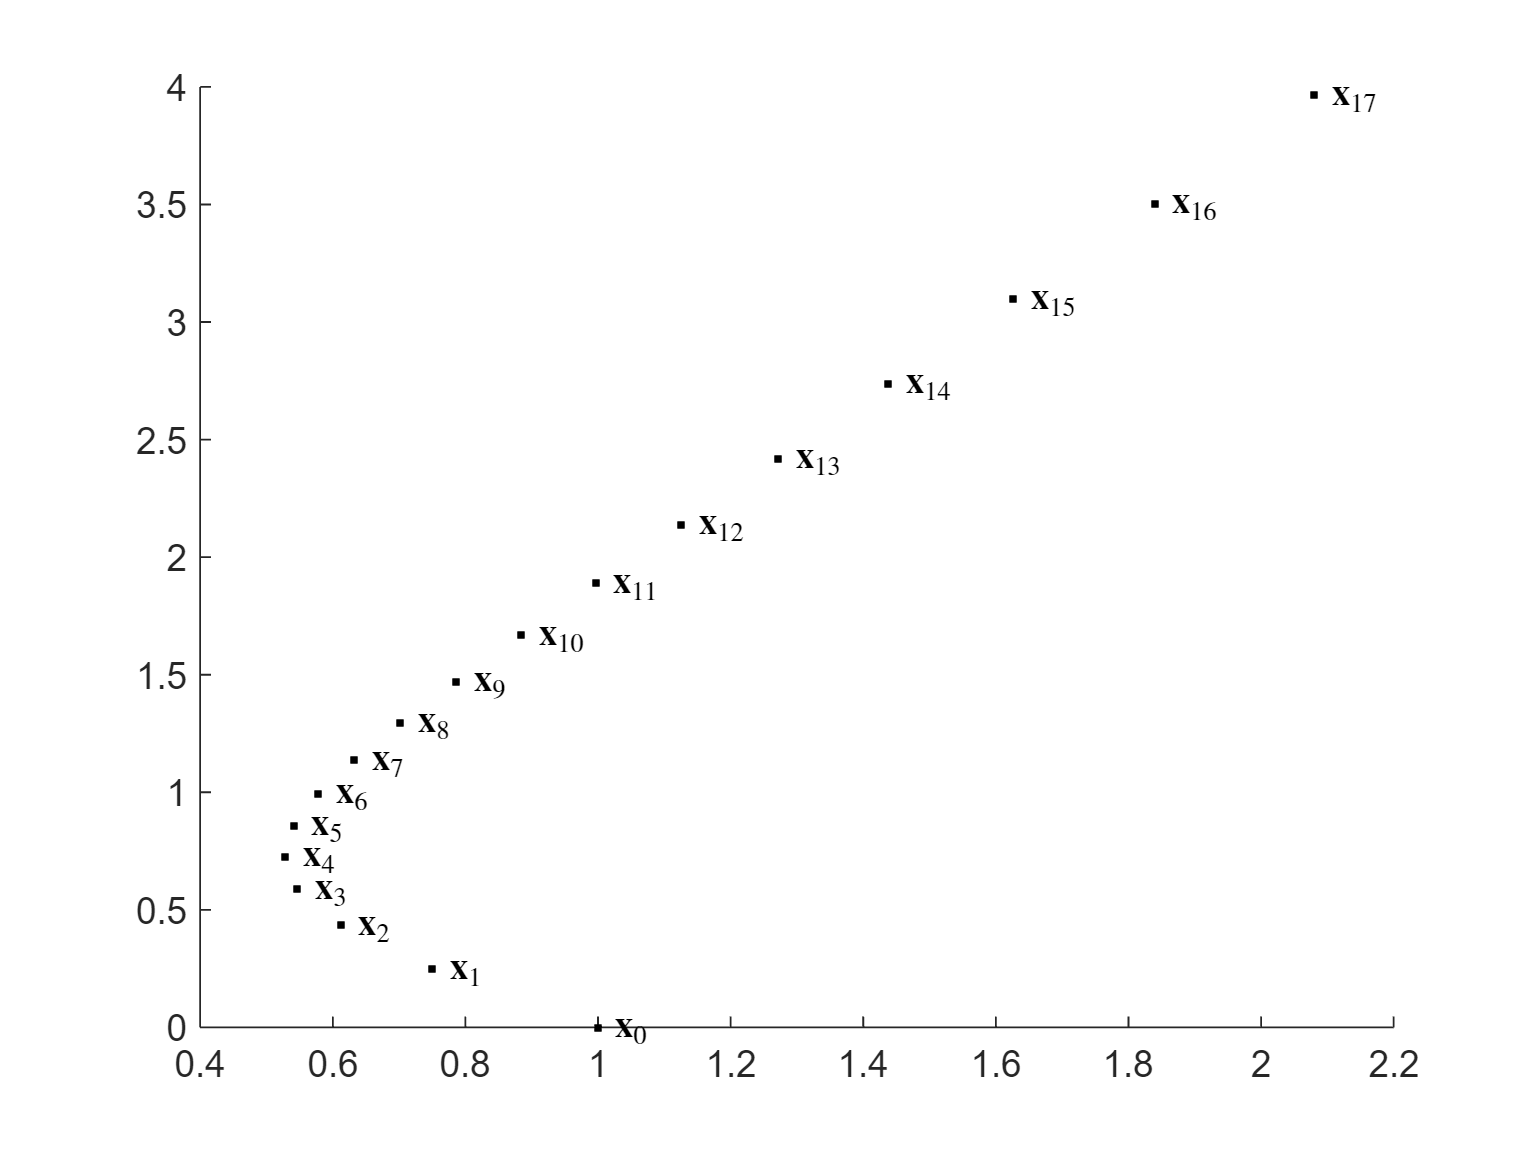

x0=[1;0];
ldseq([3/4 1/5; 1/4 1],x0,50)

**Example III.3.2.    **$A=\left[\matrix{\cos(\Phi) & -\sin(\Phi)\cr  \sin(\Phi) & \cos(\Phi)}\right]\qquad \Phi=\frac1{10}\qquad{\bf x}_0=\left[\matrix{1\cr0}\right]$

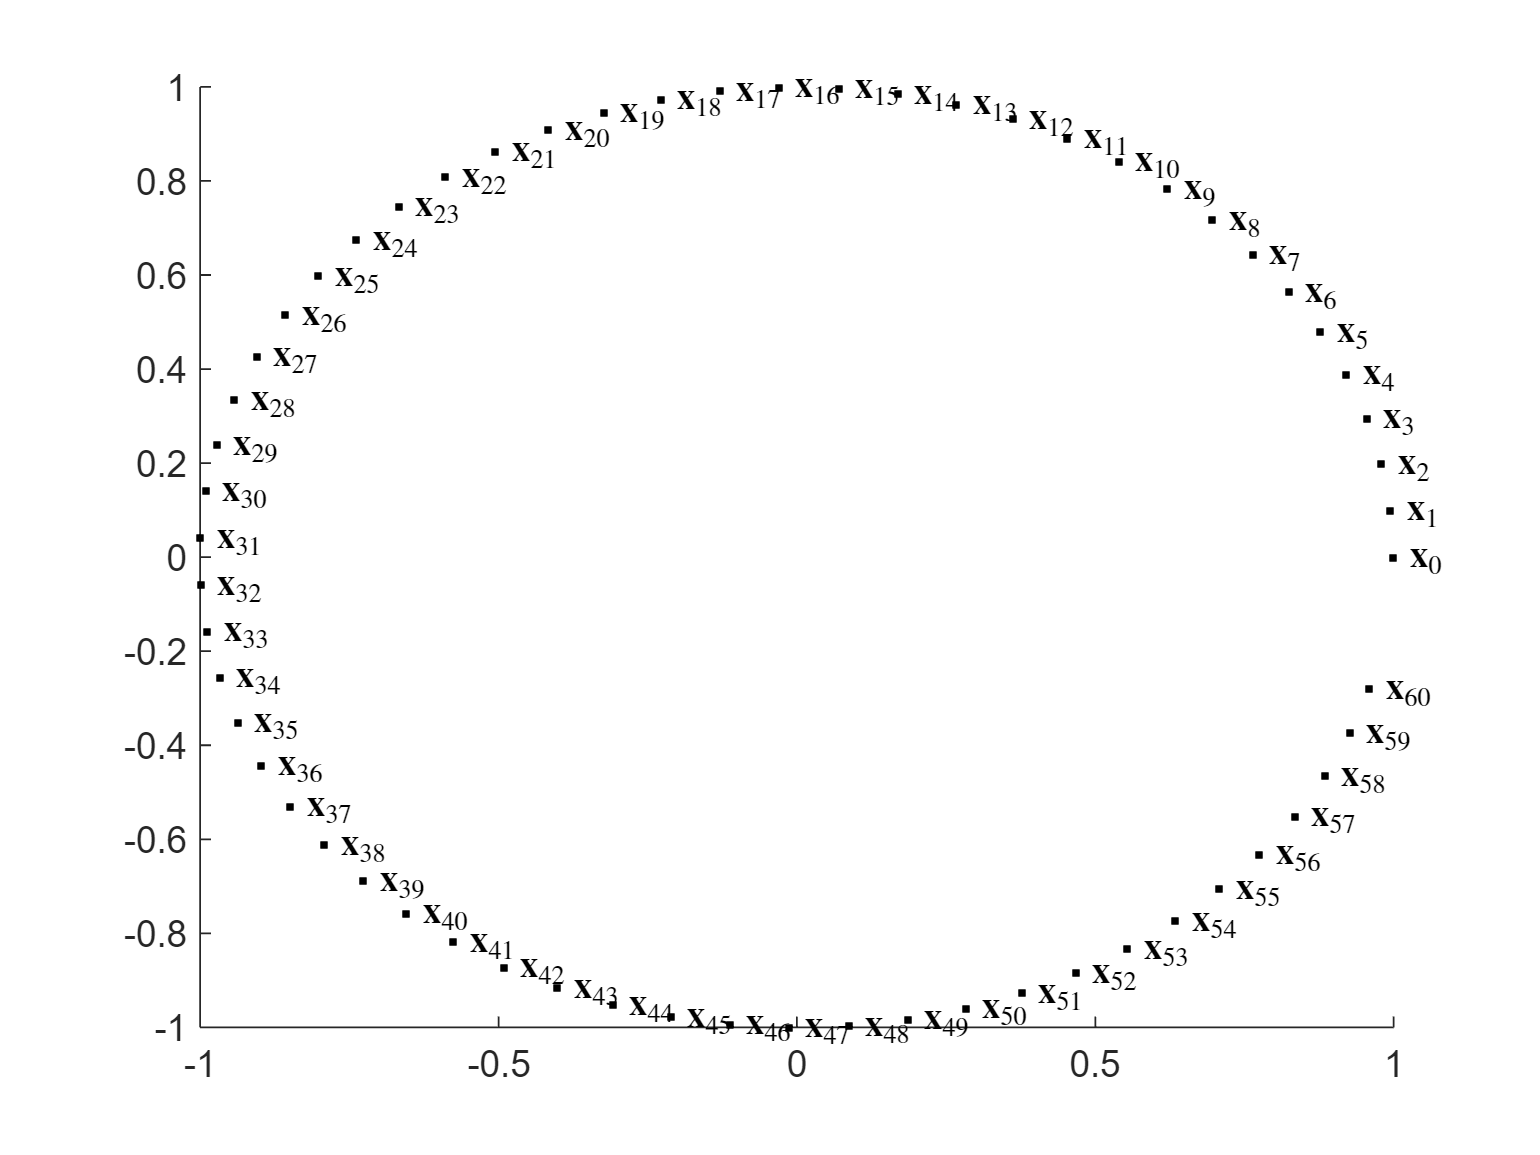

ldseq([cos(0.1) -sin(0.1); sin(0.1) cos(0.1)],x0,60)

**Example III.3.3.    **$A=\rho\left[\matrix{\cos(\Phi) & -\sin(\Phi)\cr  \sin(\Phi) & \cos(\Phi)}\right]\qquad \rho=\frac{49}{50}\qquad \Phi=\frac1{5}\qquad{\bf x}_0=\left[\matrix{1\cr0}\right]$

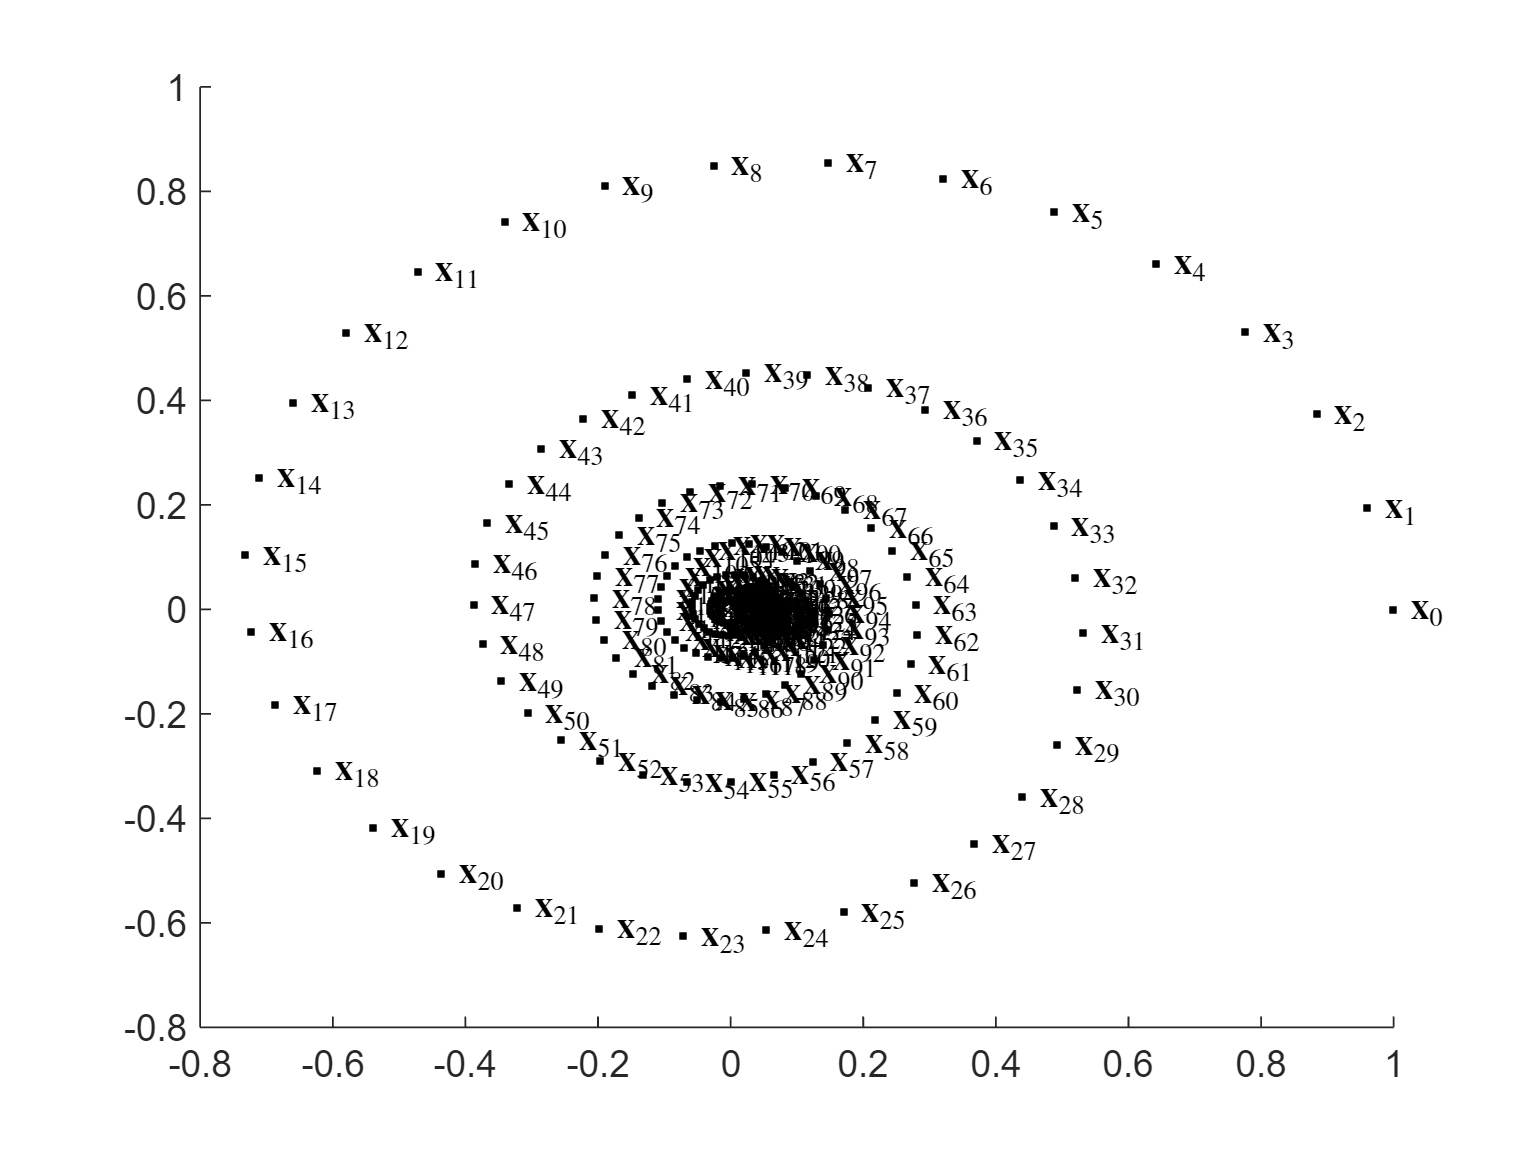

ldseq(0.98*[cos(0.2) -sin(0.2); sin(0.2) cos(0.2)],x0,200)

**Example III.3.4.    **$A=\left[ \matrix{\frac7{8} & \frac1{9}\cr \frac{1}{8} & \frac{8}{9}} \right] \qquad{\bf x}_0=\left[\matrix{1\cr0}\right]$

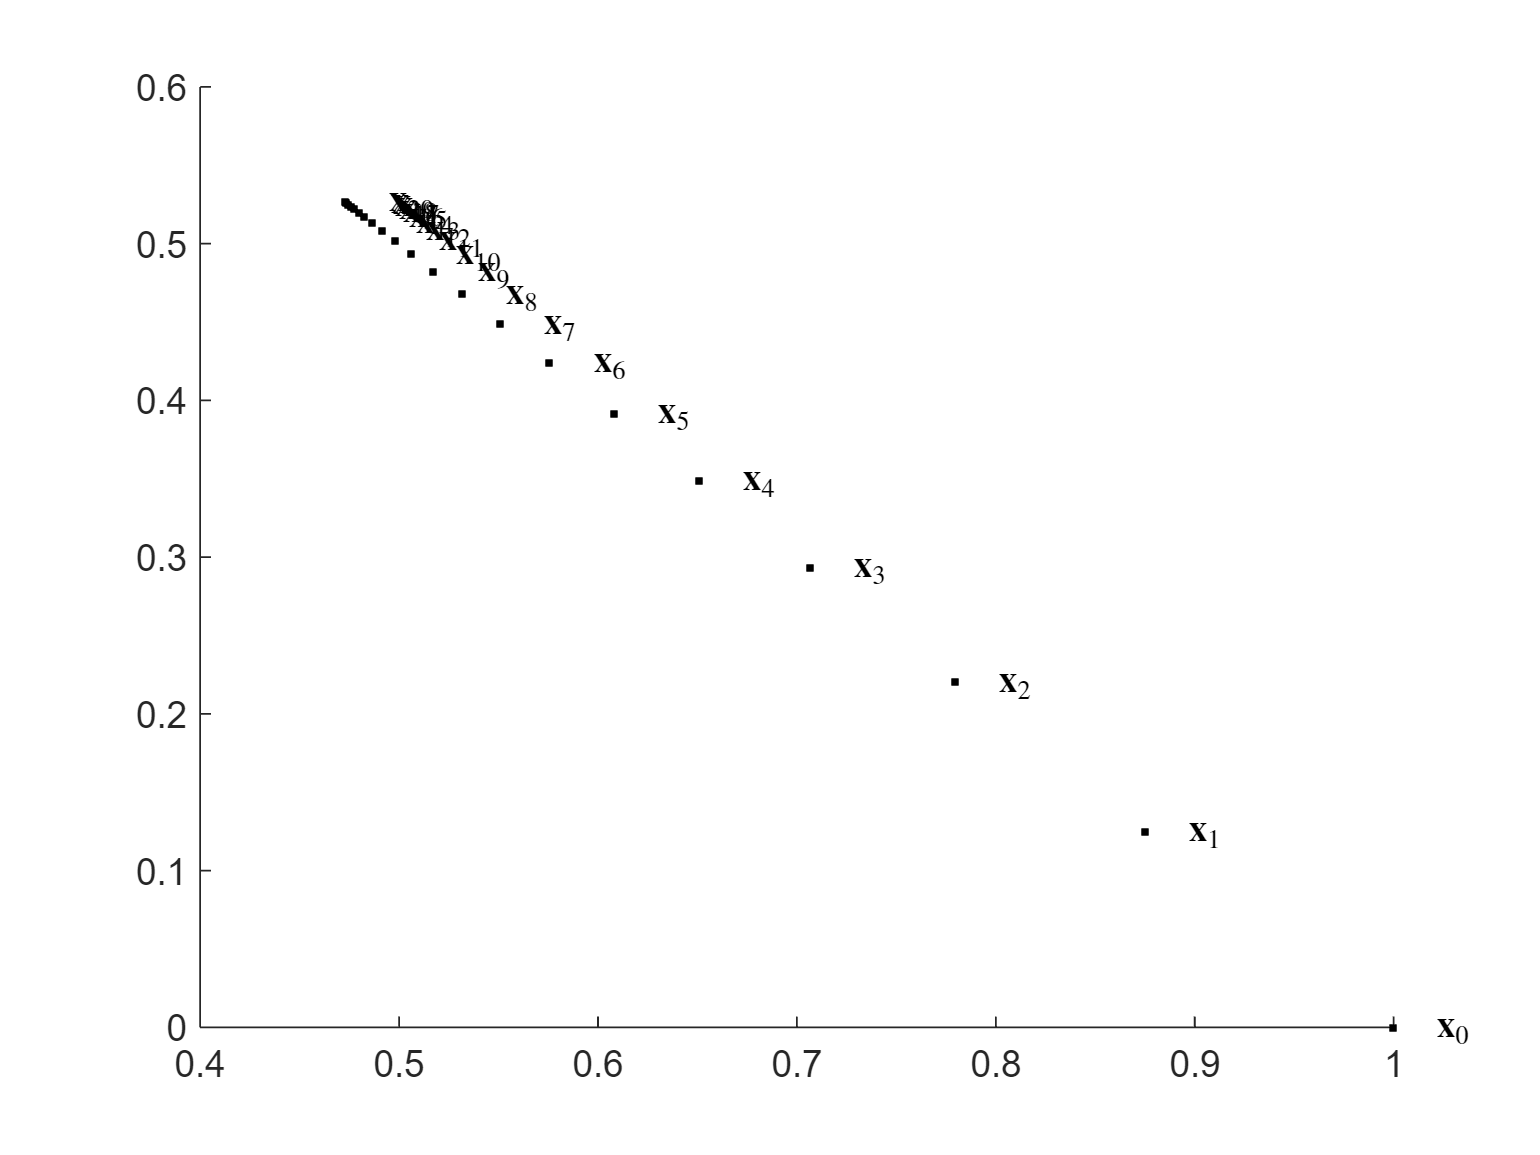

ldseq([7/8 1/9; 1/8 8/9],x0,20)

In all cases, the $\ell^\text{th}$ term in the sequences can be written in terms of powers of the matrix $A$:

        (III.3.1b)        ${\bf x}_\ell=A^\ell {\bf x}_0$.

When the matrix $A$ is diagonalizable, the solution is a linear combination of the eigenvectors with the powers of the eigenvalues as coefficients.   That is, if $A=\left[\matrix{{\bf v}_1&{\bf v}_2 &\cdots&{\bf v}_n}\right]~D~ \left[\matrix{{\bf v}_1&{\bf v}_2 &\cdots&{\bf v}_n}\right]^{-1}$, then

        (III.3.2)          ${\bf x}_\ell=A^\ell {\bf x}_0=
\left[\matrix{{\bf v}_1&{\bf v}_2 &\cdots&{\bf v}_n}\right]\left[\matrix{\lambda_1^\ell \cr &\lambda_2^\ell\cr \cr &&&\lambda_n^\ell}\right] \left[\matrix{{\bf v}_1&{\bf v}_2 &\cdots&{\bf v}_n}\right]^{-1}{\bf x}_0~=~ \lambda_1^\ell{\bf w}_1+\lambda_2^\ell{\bf w}_2+\cdots+\lambda_n^\ell{\bf w}_n$

where

        (III.3.3)        ${\bf w}_j= s_j{\bf v}_j$    and    $\left[\matrix{s_1\cr s_2\cr \vdots\cr s_n}\right]= \left[\matrix{{\bf v}_1&{\bf v}_2 &\cdots&{\bf v}_n}\right]^{-1}{\bf x}_0$

From (III.3.2) much information about the long-time behavior of the sequence of iterates can often be deduced.   

**Decay to 0****:    **Suppose that the magnitude of all the eigenvalues is less than 1, i.e., $|\lambda_j|<1\quad\text{for}\quad j=1,\dots,n$, then $\lambda_j^\ell\to0\quad\text{as}\quad\ell\to\infty\quad\text{for}\quad j=1,\dots,n$ and hence ${\bf x}_\ell\to{\bf 0}~\text{ as }~\ell\to\infty.$   Example III.3.3 is an instance of this phenomenon.   

**Convergence to a general limit****:**  Suppose that $\lambda_1=1$ and the remaining eigenvalues have magnitudes less than 1, then ${\bf x}_\ell\to {\bf w}_1$ as $\ell\to\infty$. Example III.3.4 is an instance of this phenomenon.   This case is easily generalized to the situation where one or more of the eigenvalues equals 1 with the remaining having magnitude less than 1.

**Divergence in an eigendirection****:**  Suppose that $\lambda_1>1$ and the remaining eigenvalues have magnitude less than 1.    Then for large values of ${\bf x}_\ell=\lambda_1^\ell {\bf w}_1$.   Example IIIl.1.1 is an instance of this phenomenon.   This case generalizes considerable to the case where there is one eigenvalue having a magnitude larger than all the others; for large values of $\ell$ the solution is dominated by the term associated with the eigenvalue even if the other terms are not all converging to zero.

From the above cases (and many more), it is evident that knowing the spectrum of a matrix gives considerable insight into the behavior of the iterates of the action of the matrix.

**Fibonacci numbers.   **Each term in the Fibonacci sequence from the second on equals the sum of the previous two:

        (III.3.4)        $F_{n+2}=F_{n+1}+F_{n}$

We supplement this equation with the trivial equation to obtain a system that can be written in matrix form:

        (III.3.5)        $\left\{\matrix{F_{n+2}&=&F_{n+1} ~+~ F_n \cr F_{n+1} &=&F_{n+1} \qquad\quad}\right. \qquad\Rightarrow\qquad
\left[\matrix{F_{n+2}\cr F_{n+1}}\right]=\left[\matrix{1&1\cr1&0}\right]\left[\matrix{F_{n+1}\cr F_n}\right]
$

Hence the problem can be written in the form of (III.3.1a) ${\bf x}_{n+1}=A{\bf x}_n$ where

        (III.3.6)        $A=\left[\matrix{1&1\cr1&0}\right]$    and     ${\bf x}_n=\left[\matrix{F_{n+1}\cr F_n}\right]$.

With the initial condition ${\bf x}_0=\left[\matrix{F_1\cr F_0}\right]=\left[\matrix{1\cr0}\right]$ the "solution" is given by (III.3.1b):

        (III.3.7a)        $\left[\matrix{F_{n+1}\cr F_n}\right]=\left[\matrix{1 & 1 \cr 1 & 0 }\right]^n\left[\matrix{1\cr 0}\right]$.

Diagonalization simplifies this solution:

clearvars      % remove previously defined variables from memory
[S,D]=eig(sym([1 1; 1 0]))

$$S = \left(\begin{array}{cc} \frac{1}{2}-\frac{\sqrt{5}}{2} & \frac{\sqrt{5}}{2}+\frac{1}{2}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} \frac{1}{2}-\frac{\sqrt{5}}{2} & 0\\ 0 & \frac{\sqrt{5}}{2}+\frac{1}{2} \end{array}\right)$$

inv(S)

$$ans = \left(\begin{array}{cc} -\frac{\sqrt{5}}{5} & \frac{\sqrt{5}\,\left(\sqrt{5}+1\right)}{10}\\ \frac{\sqrt{5}}{5} & \frac{\sqrt{5}\,\left(\sqrt{5}-1\right)}{10} \end{array}\right)$$

That is,

        (III.3.7b)        $\left[\matrix{F_{n+1}\cr F_n}\right]=
\left[\matrix{\frac{1-\sqrt{5}}{2} & \frac{1+\sqrt{5}}{2} \cr 1 & 1 }\right]
\left[\matrix{\left(\frac{1-\sqrt{5}}{2}\right)^n & 0 \cr 0 & \left(\frac{1+\sqrt{5}}{2}\right)^n}\right]
\left[\matrix{-\frac{\sqrt{5}}{5} & \frac{5+\sqrt{5}}{10} \cr \frac{\sqrt{5}}{5} & \frac{5-\sqrt{5}}{10} }\right]\left[\matrix{1\cr 0}\right]$

                                         
$$=\left[\matrix{\left(\frac{1-\sqrt{5}}{2}\right)^{n+1} & \left(\frac{1+\sqrt{5}}{2}\right)^{n+1} \cr \left(\frac{1-\sqrt{5}}{2}\right)^{n} & \left(\frac{1+\sqrt{5}}{2}\right)^{n}}\right]
\left[\matrix{-\frac{\sqrt{5}}{5} \cr \frac{\sqrt{5}}{5}}\right]$$


                                         
$$=\left[\matrix{-\frac{\sqrt{5}}{5} \left(\frac{1-\sqrt{5}}{2}\right)^{n+1} +\frac{\sqrt{5}}{5} \left(\frac{1+\sqrt{5}}{2}\right)^{n+1} \cr 
-\frac{\sqrt{5}}{5} \left(\frac{1-\sqrt{5}}{2}\right)^{n} +\frac{\sqrt{5}}{5} \left(\frac{1+\sqrt{5}}{2}\right)^{n}}\right]
$$


Extracting and simplifying the second component of this vector recovers the Binet formula (I.1.10):

        (III.3.7c)       $F_n= \frac{\sqrt{5}}{5}\left[ \left(\frac{1+\sqrt{5}}{2}\right)^{n}-\left(\frac{1-\sqrt{5}}{2}\right)^{n}\right]=\frac{\sqrt{5}}{5}\bigg[\varphi^n-(-\varphi)^{-n}\bigg]$    where    $\varphi=\frac{1+\sqrt{5}}{5}$.

 **General second-order linear difference equation.**   The Fibonacci difference equation (III.3.4) is a special instance of the general second-order linear difference equations

        (III.3.8)        $y_{n+2}=a y_{n+1}+by_n$.

This can be written in the matrix form of (III.3.1) ${\bf x}_{n+1}=A{\bf x}_n$ where

        (III.3.9)        $A=\left[\matrix{a&b\cr1&0}\right]$    and     ${\bf x}_n=\left[\matrix{y_{n+1}\cr y_n}\right]$.

Diagonalization (performed by MATLAB below) gives formulas for the solution.

[S,D]=eig([sym("a") sym("b"); 1 0])

$$S = \left(\begin{array}{cc} \frac{a}{2}-\frac{\sqrt{a^{2}+4\,b}}{2} & \frac{a}{2}+\frac{\sqrt{a^{2}+4\,b}}{2}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} \frac{a}{2}-\frac{\sqrt{a^{2}+4\,b}}{2} & 0\\ 0 & \frac{a}{2}+\frac{\sqrt{a^{2}+4\,b}}{2} \end{array}\right)$$

S*D^sym('n')*inv(S)*[sym('y1'); sym('y0')]

$$ans = \begin{array}{l} \left(\begin{array}{c} -y_{1}\,\left(\frac{{\sigma_{1}}^{n}\,\sigma_{1}}{\sigma_{3}}-\frac{{\sigma_{2}}^{n}\,\sigma_{2}}{\sigma_{3}}\right)-y_{0}\,\left(\frac{\left(a-\sigma_{3}\right)\,{\sigma_{2}}^{n}\,\sigma_{2}}{2\,\sigma_{3}}-\frac{\left(a+\sigma_{3}\right)\,{\sigma_{1}}^{n}\,\sigma_{1}}{2\,\sigma_{3}}\right)\\ y_{0}\,\left(\frac{\left(a+\sigma_{3}\right)\,{\sigma_{1}}^{n}}{2\,\sigma_{3}}-\frac{\left(a-\sigma_{3}\right)\,{\sigma_{2}}^{n}}{2\,\sigma_{3}}\right)-y_{1}\,\left(\frac{{\sigma_{1}}^{n}}{\sigma_{3}}-\frac{{\sigma_{2}}^{n}}{\sigma_{3}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{a}{2}-\frac{\sigma_{3}}{2}\\ \sigma_{2}=\frac{a}{2}+\frac{\sigma_{3}}{2}\\ \sigma_{3}=\sqrt{a^{2}+4\,b} \end{array}$$

Hence, if $y_0=0$ and $y_1=1$ then

        (III.3.10)        $y_n=\frac{ \bigg(\frac{a+\sqrt{a^2+4b}}{2}\bigg)^n-\bigg(\frac{a-\sqrt{a^2+4b}}{2}\bigg)^n}{\sqrt{a^2+4b}}$.

**The general third-order linear difference equation.**   The general second-order linear difference equations

        (III.3.11)        $y_{n+3}=a y_{n+2}+by_{n+1}+cy_n$.

This can be written in the matrix form of (III.3.1) ${\bf x}_{n+1}=A{\bf x}_n$ where

        (III.3.12)        $A=\left[\matrix{a&b&c\cr1&0&0\cr0&1&0}\right]$    and     ${\bf x}_n=\left[\matrix{y_{n+2}\cr y_{n+1}\cr y_n}\right]$.

**Stochastic matrices and discrete-time Markov chains.    **Consider a system which can at the $n^{\text{th}}$ tick of a clock be in any one of $n$ states ${\cal S}_1,{\cal S}_2,\dots,{\cal S}_n$.   At each tick of the clock, the system has a probability $M_{ij}$ to transition to state ${\cal S}_i$ if the system is currently in state ${\cal S}_j$.   The $n\times n$ matrix $M$ having components $M_{ij}$ is known as the ***transition matrix*** of the system. This matrix has the properties that (1) it entries must be nonnegative real numbers and (2) the sum of each column must be 1.   The nonnegativity is required by the entries representing probabilities.    The sum of the columns equaling 1 is required as the probability of the system transitioning to some system must be 1.   Matrices with these two properties are called ***stochastic matrices***.    The random (or ***stochastic)*** process defined by a stochastic matrix is known as a ***Markov chain.***

**Playing with building blocks:   **Consider the task of stacking three blocks.   This process has four states.

- ${\cal S}_1$:  0 blocks successfully stacked,

- ${\cal S}_2$:  1 block successfully stacked,

- ${\cal S}_3$:  2 blocks successfully stacked,

- ${\cal S}_4$:  3 blocks successfully stacked.

We assume that each attempt to stack another block (a) may be successful resulting in a stack of blocks one higher than at the previous step or (b) may be unsuccessful resulting in zero blocks being properly stacked.

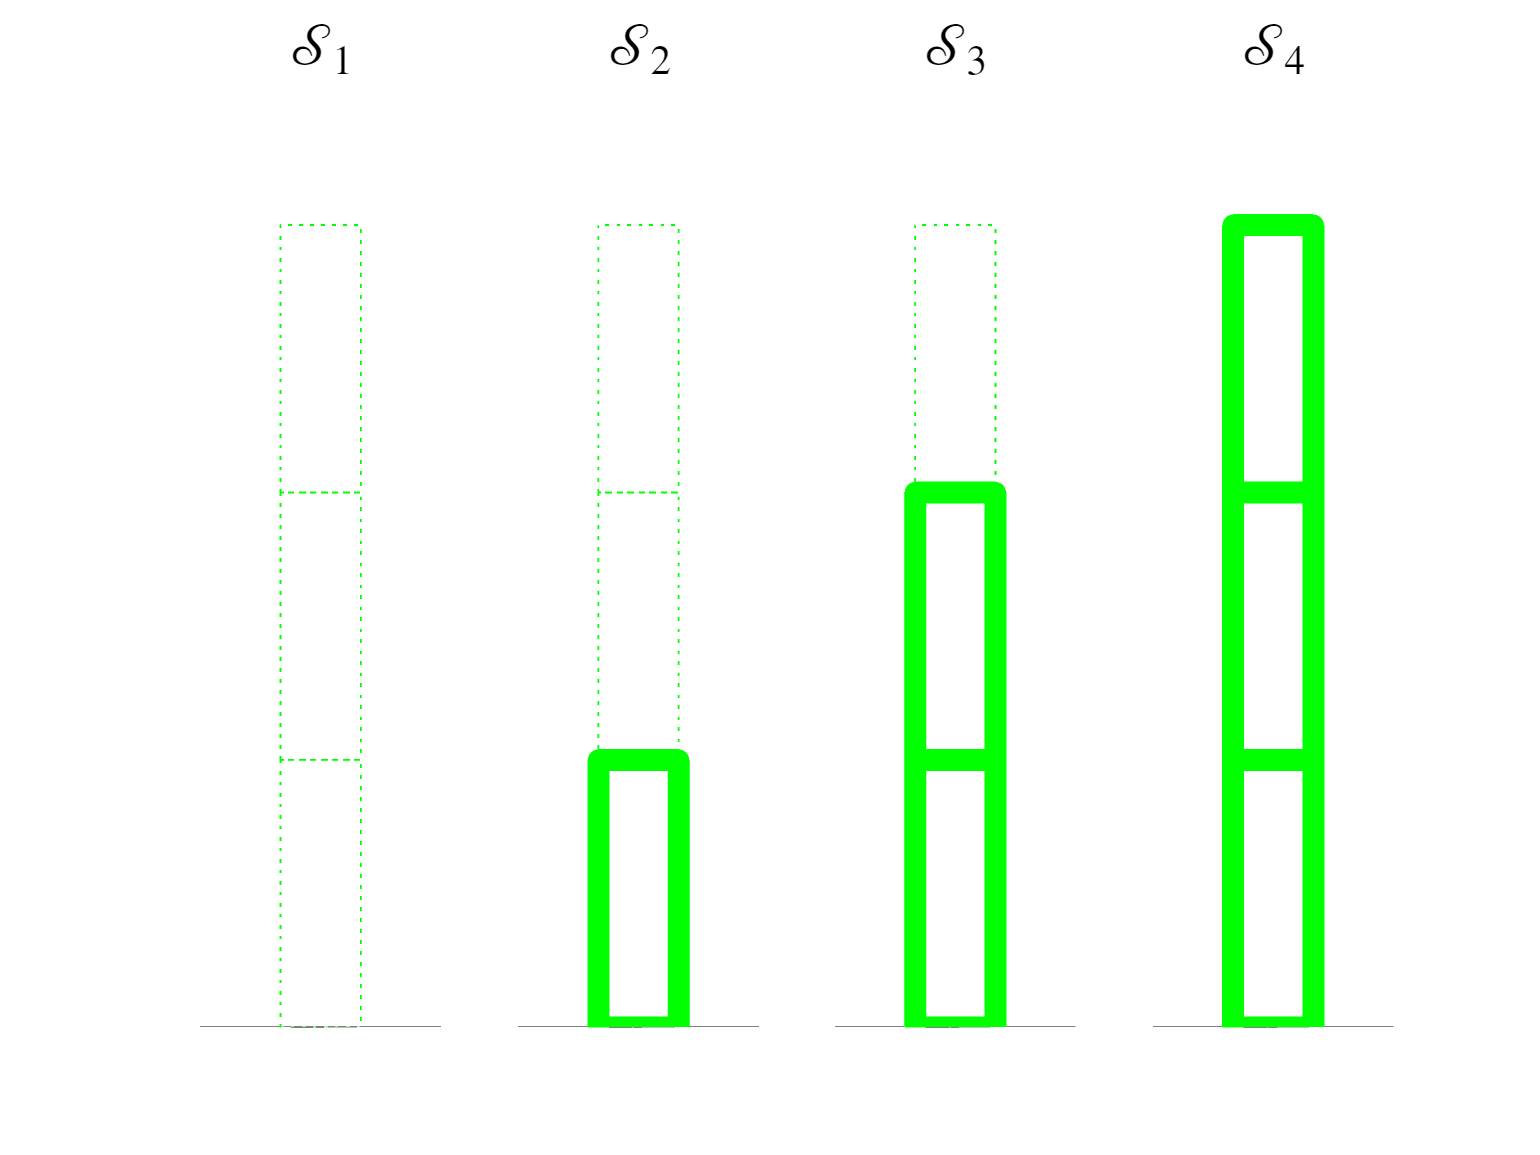

figIII1a()

We assume that

- the probability of the first block being placed successfully is $p=0.8$,

- the probability of the second block being placed successfully is $q=0.5$,

- the probability of the third block being placed successfully is $r=0.2$.

Once three blocks have been stacked successfully, the system stays in that state.

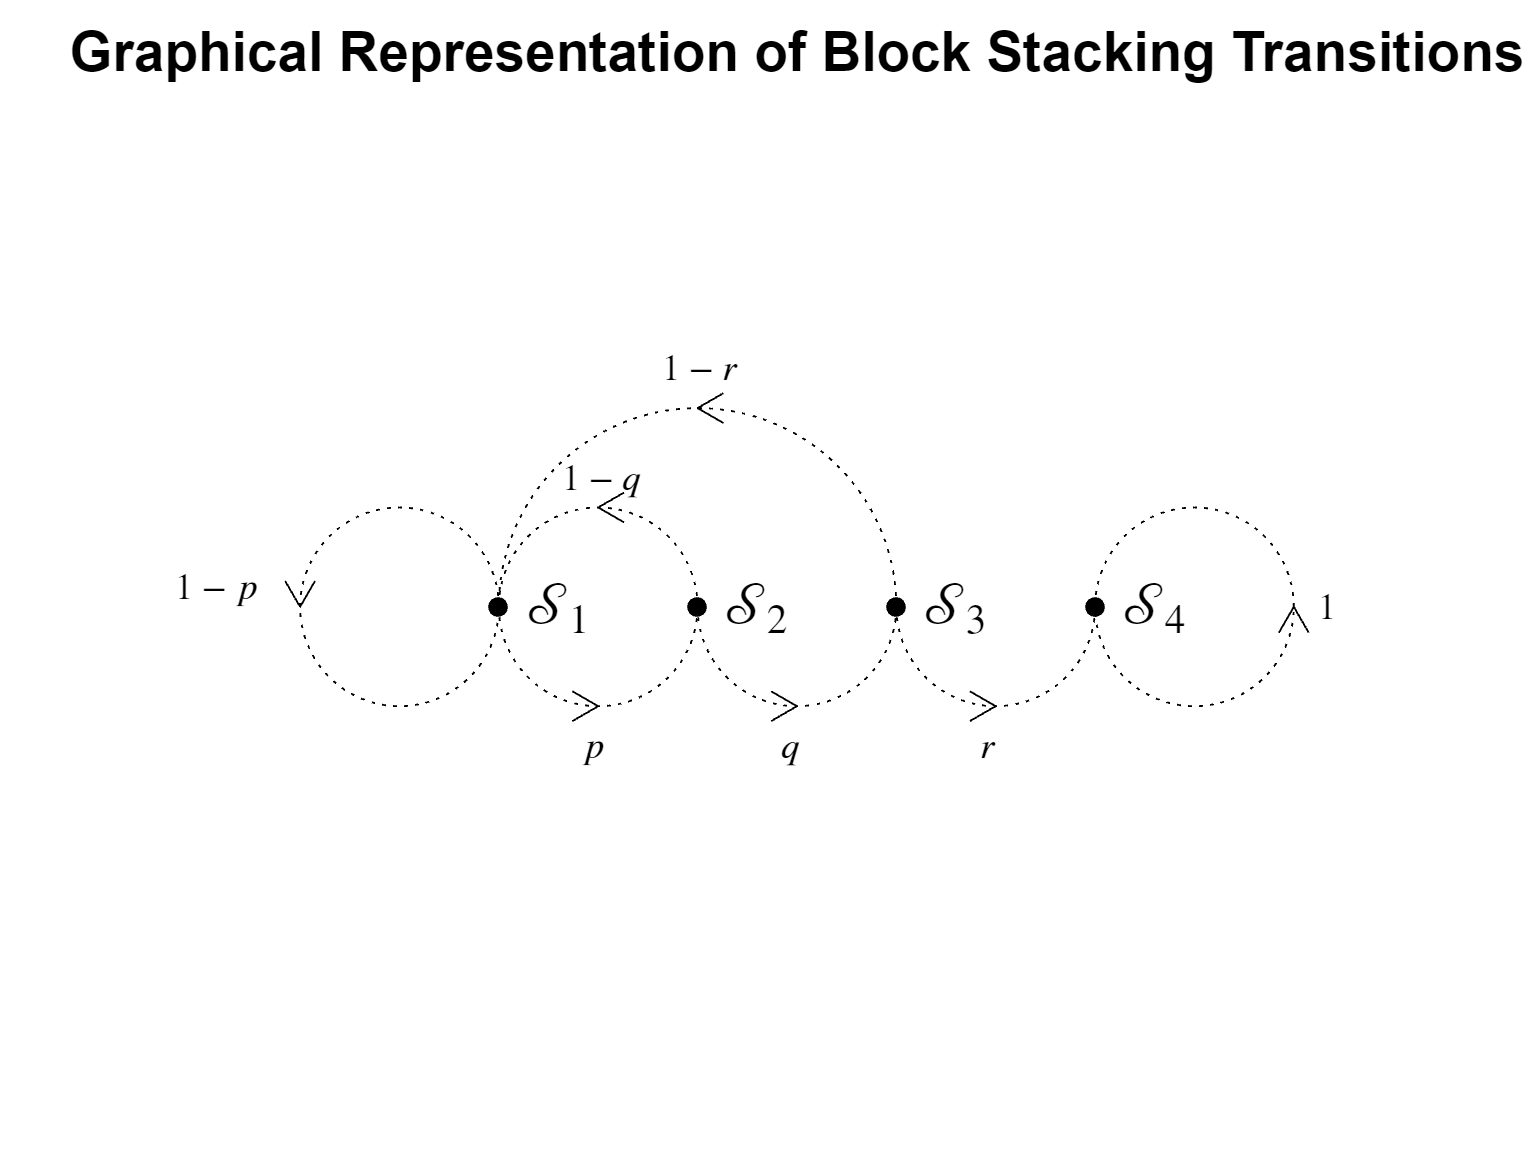

figIII1b()

The transition matrix for this system is thus

$M~=~\left[\matrix{
1-p & 1-q & 1-r & 0 \cr
p & 0 & 0 & 0 \cr
0 & q & 0 & 0 \cr
0 & 0 & r & 1 \cr}\right]~=~\left[\matrix{
0.2 & 0.5 & 0.8 & 0 \cr
0.8 & 0 & 0 & 0 \cr
0 & 0.5 & 0 & 0 \cr
0 & 0 & 0.2 & 1.0 \cr
}\right]$.

Because the transitions between states have a random element, the specific sequence of states occurring after the initial state ${\cal S}_0$, will occur differently is uncertain.   Eight instances of this process are shown below.

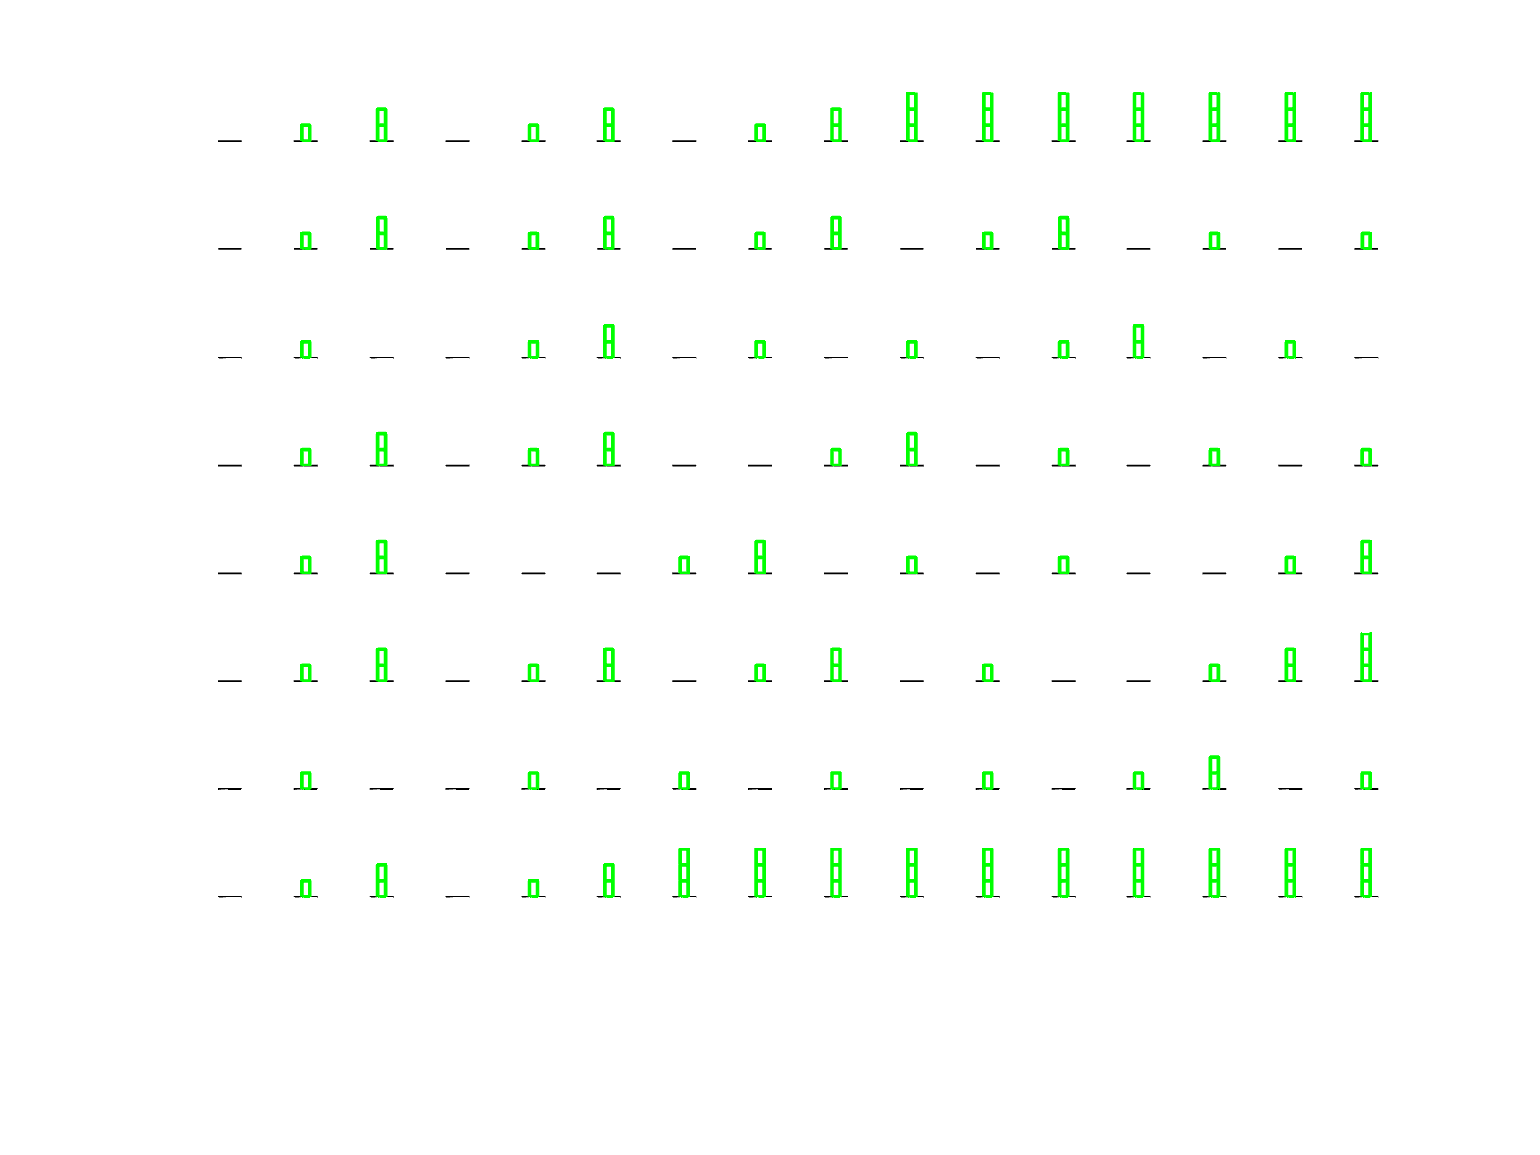

M=[0.2 0.5 0.8 0.0; 0.8 0.0 0.0 0.0; 0.0 0.5 0.0 0.0; 0.0 0.0 0.2 1.0];
figIII1c(8,15,M)

Here each row displays a different instance of the stacking process.    The left most end of each row represents the initial state, which is always${\cal S}_0$ in this example, and subsequent states are displayed to the right.    

In the stacking process, it is inevitable that eventually three blocks will be successfully stacked and the system remains in that state ${\cal S}_4$ from that point on.  States from which it is impossible to leave are called ***absorbing states***.

While it is guaranteed (as probabilist say "with probability 1") that the absorbing state for this system will be reached, it is however also exceedingly likely that reaching this state will require more than one try--that is, it is likely that state ${\cal S}_1$ will be visited more than once.    For the process described above, the probability of starting in state ${\cal S}_1$ and reaching the absorbing state ${\cal S}_4$ without an "accident" (revisiting state ${\cal S}_1$) is $pqr=(0.8)(0.5)(0.2)=0.08$.    

Because of the random nature of the transitions between states in a Markov chain, it is impossible to predict with certainty the state of the system beyond the initial state.   Hence, we use a ***stochastic vector ***which gives the probability of the system being in each of it possible states.  For a system with $n$ states a stochastic vector is a vector in ${\mathbb R}^n$ with nonnegative entries summing to one.  (Note:  the columns of a stochastic matrix are stochastic vectors.)  For a Markov chain the $i^{\text{th}}$component will equal to the probability of the system being in the $i^{\text{th}}$state ${\cal S}_i$.    

Because of the transitions that occur in a Markov chain, the probability of being in a particular state will generally change depending on the number of transitions that have occurred previously.    Hence, we expect to have a sequence of stochastic vectors ${\bf p}_0,{\bf p}_1,{\bf p}_2,\dots$where ${\bf p}_\ell$ gives the probability of being in any of the $n$ states of the system after $\ell$ transitions.   Because we are assuming that the block stacking process is initially in state ${\cal S}_1$ we have

         (III.3.13)        ${\bf p}_0=\left[\matrix{1\cr0\cr0\cr0}\right]$.

Using the methods of conditional probability, it can be shown that ${\bf p}_{\ell+1}=M{\bf p}_\ell$.   That is, updating the probability vector for a Markov chain is done through multiplication by the transition matrix.    For the block stacking examples, that means 

        (III.3.14)        ${\bf p}_1=\left[\matrix{
1-p & 1-q & 1-r & 0 \cr
p & 0 & 0 & 0 \cr
0 & q & 0 & 0 \cr
0 & 0 & r & 1 \cr}\right]\left[\matrix{1\cr0\cr0\cr0}\right]=\left[\matrix{1-p\cr p\cr0\cr0}\right]$.

So after the first transition either there is one block successfully stacked (which occurs with probability $p$) or there are no blocks stacked (which occurs with probability $1-p$).   After two transitions,

        (III.3.15)        ${\bf p}_2=\left[\matrix{
1-p & 1-q & 1-r & 0 \cr
p & 0 & 0 & 0 \cr
0 & q & 0 & 0 \cr
0 & 0 & r & 1 \cr}\right]\left[\matrix{1-p\cr p\cr0\cr0}\right]=\left[\matrix{(1-p)^2+p(1-q)\cr p(1-p)\cr pq\cr0}\right]$.

So after two transitions, the system is in state ${\cal S}_1$ with probability $(1-p)^2+p(1-q)$, in state ${\cal S}_2$ with probability $p(1-p)$ or in state ${\cal S}_3$ with probability $pq$.   After two transitions, the first state ${\cal S}_1$ can be reached is two ways:

        ${\cal S}_1\quad\to\quad{\cal S}_1\quad\to\quad{\cal S}_1$    occurs with probability    $(1-p)^2$        (two failures to stack the first block)

        ${\cal S}_1\quad\to\quad{\cal S}_2\quad\to\quad{\cal S}_1$    occurs with probability    $p(1-q)$        (success with first block but failure with the second)

In a sense, the matrix multiplication formalism automatically accounts for all the different ways a state can be reached.  After three transitions,

       (III.3.16)        ${\bf p}_3=\left[\matrix{
1-p & 1-q & 1-r & 0 \cr
p & 0 & 0 & 0 \cr
0 & q & 0 & 0 \cr
0 & 0 & r & 1 \cr}\right]\left[\matrix{(1-p)^2+p(1-q)\cr p(1-p)\cr pq\cr0}\right]=\left[\matrix{(1-p)^3+2p(1-p)(1-q)+pq(1-r)\cr p(1-p)^2+p^2(1-q)\cr pq(1-p)\cr pqr}\right]$.

Since we have assigned numerical values to the transition probabilities $p,~q~\text{and}~r$, it is straightforward to use MATLAB to compute and plot $p_\ell$ for $\ell$ over some reasonable range.

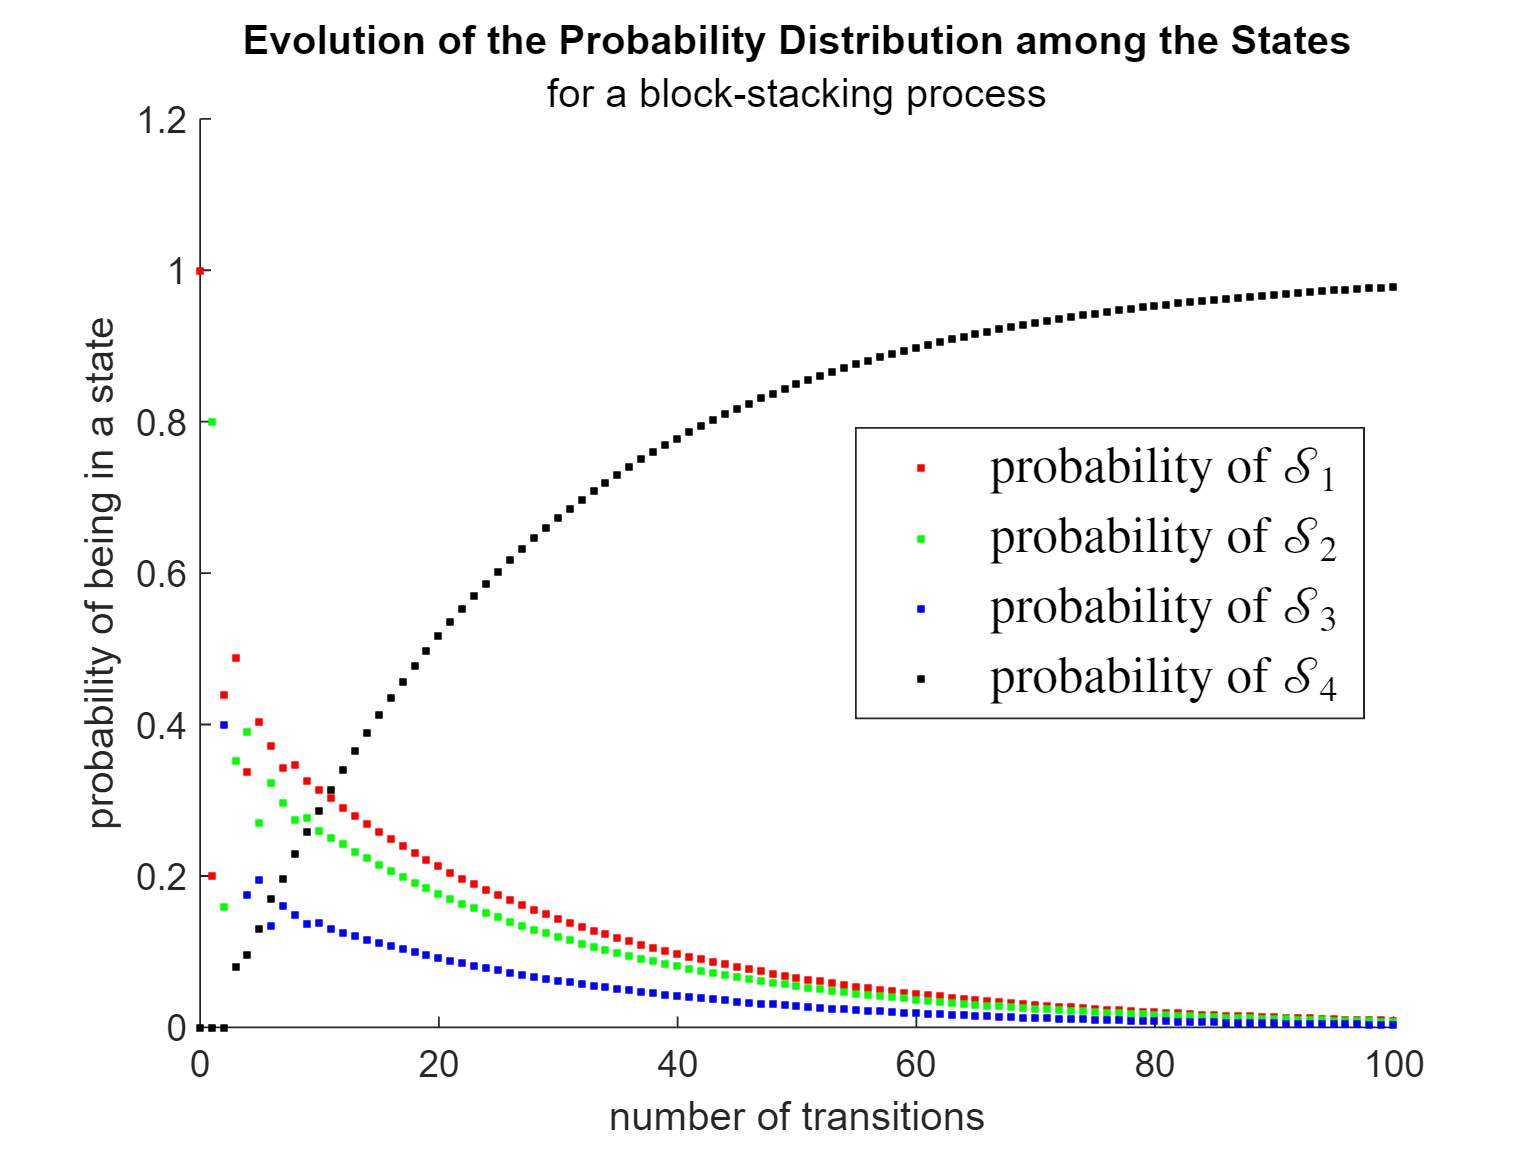

figIII1d(M)

From the above figure, we see that eventually all the probability accumulates on the absorbing state ${\cal S}_4$.  That is,

        $\lim_{\ell\to\infty} p_\ell=\left[\matrix{0\cr0\cr0\cr1}\right]$         which implies that    $M\left[\matrix{0\cr0\cr0\cr1}\right]=\left[\matrix{0\cr0\cr0\cr1}\right]$, i.e, $\left[\matrix{0\cr0\cr0\cr1}\right]$ is an eigenvector of $M$with eigenvalue 1.

A probability vector that is an eigenvector of a transition matrix with eigenvalue 1 is called a ***stationary distribution***.   For a Markov chain with an absorbing state there is always a stationary distribution associated with that state.  However, Markov chains without absorbing states will still have ***stationary distributions***.   Consider a modification of the block-stacking process where instead of the stack of three blocks standing forever there is a chance $\epsilon=0.1$ of the blocks falling.   The modified transition matrix is then

$M~=~\left[\matrix{
1-p & 1-q & 1-r & \epsilon \cr
p & 0 & 0 & 0 \cr
0 & q & 0 & 0 \cr
0 & 0 & r & 1-\epsilon \cr}\right]~=~\left[\matrix{
0.2 & 0.5 & 0.8 & 0.1 \cr
0.8 & 0 & 0 & 0 \cr
0 & 0.5 & 0 & 0 \cr
0 & 0 & 0.2 & 0.9 \cr
}\right]$.

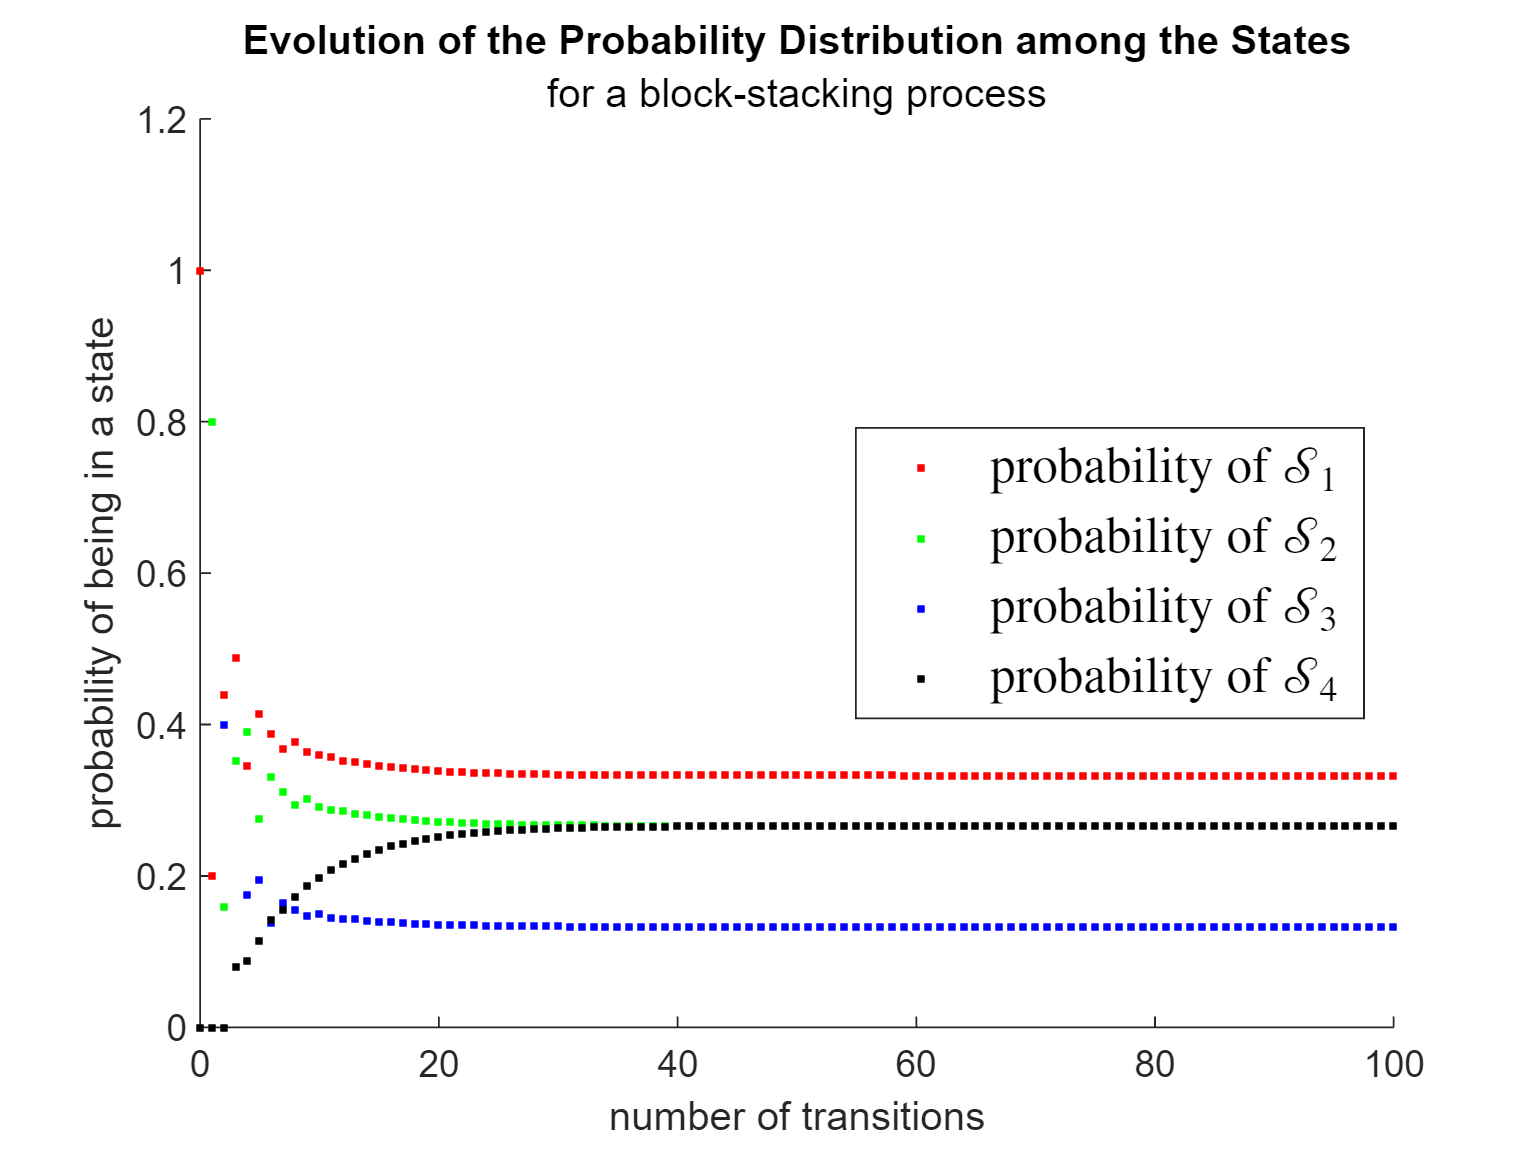

M=[0.2 0.5 0.8 0.1; 0.8 0.0 0.0 0.0; 0.0 0.5 0.0 0.0; 0.0 0.0 0.2 0.9];
figIII1d(M)

Despite the ongoing process of rebuilding the stack after an infinite sequence of falls, we see the probability of finding the system in any particular state settles down each to a nonzero value.    With a bit of effort, we can calculate the stationary distribution exactly:

        ${\bf w}~=~\frac{1}{15}\left[\matrix{5\cr4\cr2\cr4}\right]\approx
\left[\matrix{0.3333\cr 0.2667\cr 0.1333\cr 0.2667}\right]$.

It can be shown that every stochastic matrix has a stationary distribution.   This demonstration begins with the observation that the transpose of stochastic matrix $A^T$ always has an eigenvalue of 1; since the sum of the entries in a row $A^T$ equals to 1:  $A^T \left[\matrix {1 & 1 & \cdots & 1}\right]^T~=~1~\left[\matrix {1 & 1 & \cdots & 1}\right]^T$.   Thus, $1\in\sigma(A^T)$.   But because $P_A(\lambda)=|A-\lambda I|=|A^T-\lambda I|=P_{A^T}(\lambda)$, $\sigma(A)=\sigma(A^T)$.   Hence, $1\in\sigma(A)$.    Moreover, the eigenvector of $A$ associated with the eigenvalue 1 can be chosen to be a stochastic vector (Perron-Frobenius Theorem).   Finally, it can be shown that eigenvalues of a stochastic matrix all fall in or on the unit circles.   That is, if $\lambda=a+bi$ then $a^2+b^2\le1$.

**Phase curves.  **From (III.3.2) and (III.3.3) the iterates of a matrix $A$ with initial value ${\bf x}_0$ are given by

        (III.3.17)        ${\bf x}_\ell~=~\lambda_1^\ell s_1{\bf v}_1~+~
\lambda_2^\ell s_2{\bf v}_2~+~\cdots~+~ \lambda_n^\ell s_n{\bf v}_n$

where $s_1,s_2,\dots,s_n$ are the expansion coefficients for ${\bf x}_0$.    It follows that the sequence of iterates fall on the curve

        (III.3.18)        ${\bf x}_t~=~\lambda_1^t s_1{\bf v}_1~+~
\lambda_2^t s_2{\bf v}_2~+~\cdots~+~ \lambda_n^t s_n{\bf v}_n$

where the discrete parameter is replaced by $\ell$ is replaced by the continuous parameter $t$.   One such curve is known as a phase curve and the family of all the phase curves (for all possible initial conditions) is known as the phase diagram.    As a practical matter, when we plot the phase diagram, we plot only a reasonable number of the phase curves to represent the entire phase diagram.

A plot of some of the phase curves for **Example III.3.1 **with $A=\left[\matrix{3/4 & 1/5\cr  1/4 & 5/4}\right]$ is shown below.

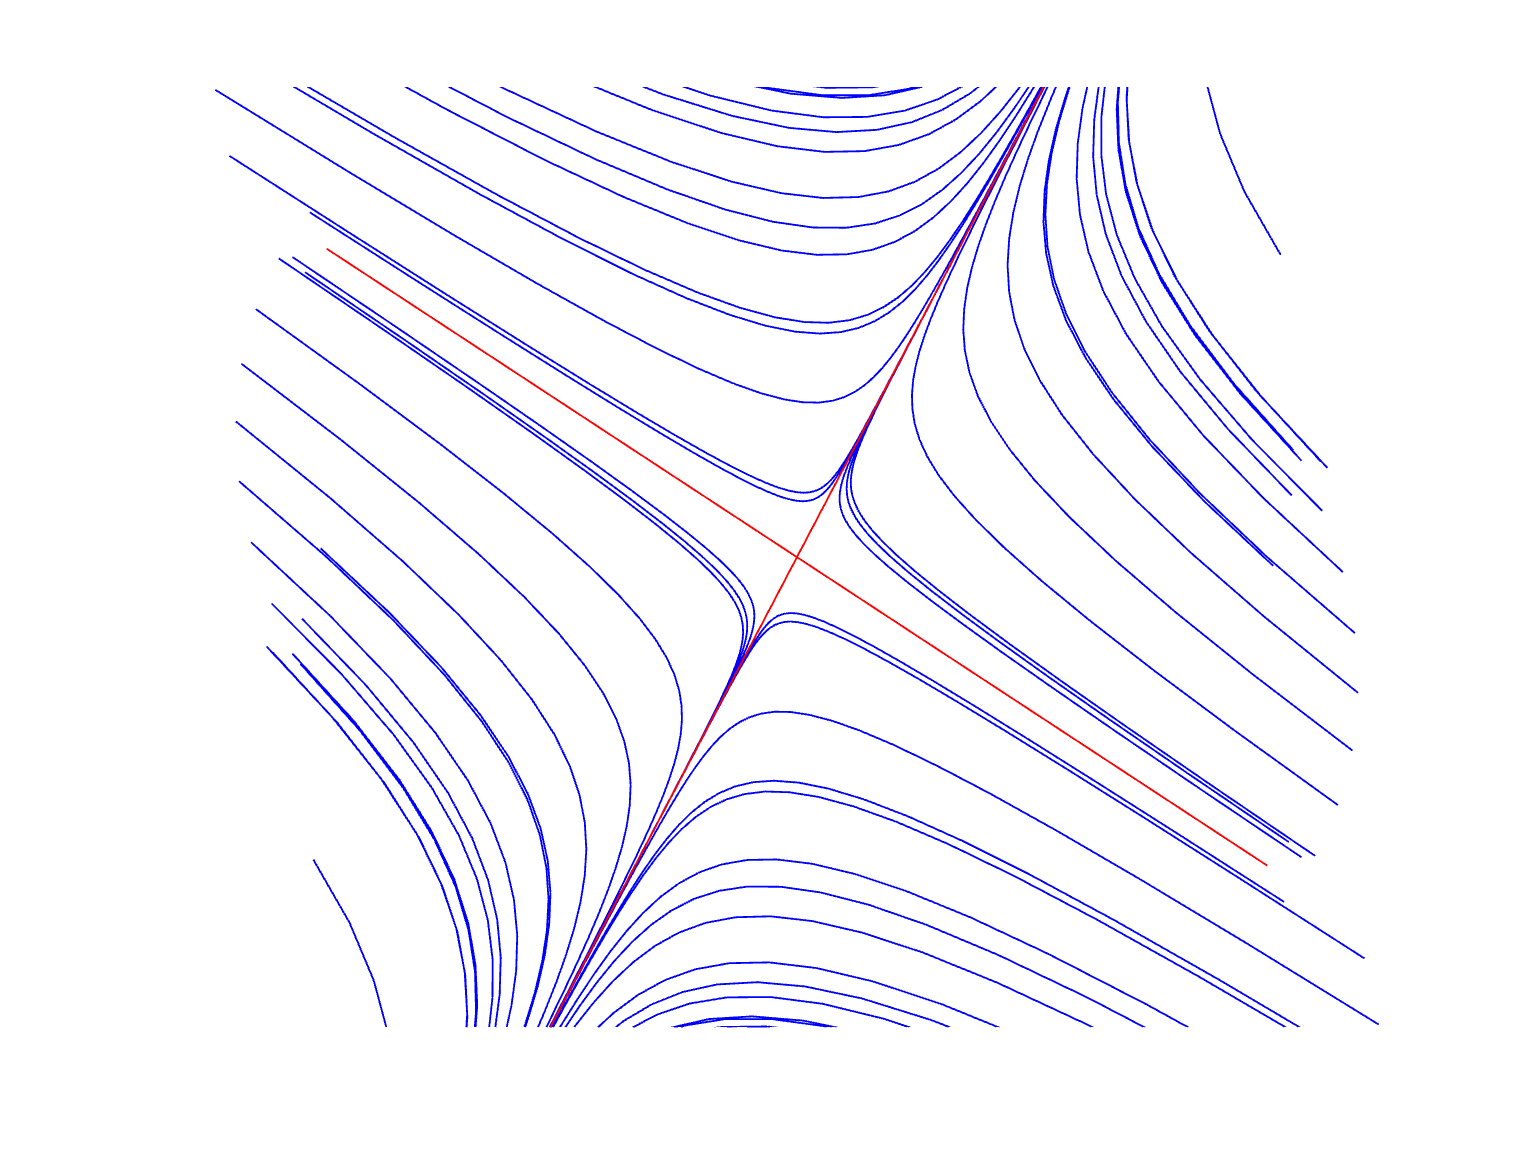

A=[3/4 1/5; 1/4 1];
x0=[ [cos(0:2*pi/50:2*pi); sin(0:2*pi/50:2*pi)]  0.2*[cos(0:2*pi/6:2*pi); sin(0:2*pi/6:2*pi)] [0.9 0.9 -0.9 -0.9; 0.9 -0.9 0.9 -0.9] ];
dt=0.5;
phase(A,dt,x0)

In this diagram, two directions, determined by the eigenvectors, stand out (marked in red).   If the initial conditions ${\bf x}_0$ is an eigenvector (i.e., lies on either of the red lines), then all the iterates $A^\ell {\bf x}_0=\lambda_k^\ell {\bf x}_0$ also lies on the line.   If the eigenvalue $\lambda_2>1$, then the iterates are moving further and further away from the origin as $\ell$ increases.   On the other hand, if the eigenvalues $0\le \lambda_1<1$, then the iterates are moving closer and closer to the origin as $\ell$ increases.    In this case,

eig(A)

ans =    0.618826230851010
   1.131173769148990


Here there is one eigenvalue greater than 1 and one between 0 and 1.    Thus, for initial conditions starting on one of the phase curves, the iterates move away from the origin, and for initial conditions starting on the other phase curve the iterates move toward the origin.    For initial conditions on neither of these two phase curves,

                    ${\bf x}_t~=~\lambda_1^t s_1{\bf v}_1~+~ \lambda_2^t s_2{\bf v}_2$    with      $0\le \lambda_1 <1<\lambda_2$,    $s_1\ne 0$    and     $s_2\ne 0$,

For large, positive values of $t$, $\lambda_1^t\to0$, so ${\bf x}_t$ is very close to the outgoing phase curve.   For large, negative values of $t$, $\lambda_2^t\to0$, so ${\bf x}_t$ is very close to the inward going phase curve.

A plot of some of the phase curves for **Example III.3.2 **with $A=\left[\matrix{\cos(\Phi) & -\sin(\Phi)\cr  \sin(\Phi) & \cos(\Phi)}\right],\quad \Phi=\frac1{10}\quad\text{and}\quad{\bf x}_0=\left[\matrix{1\cr0}\right]$ is shown below.

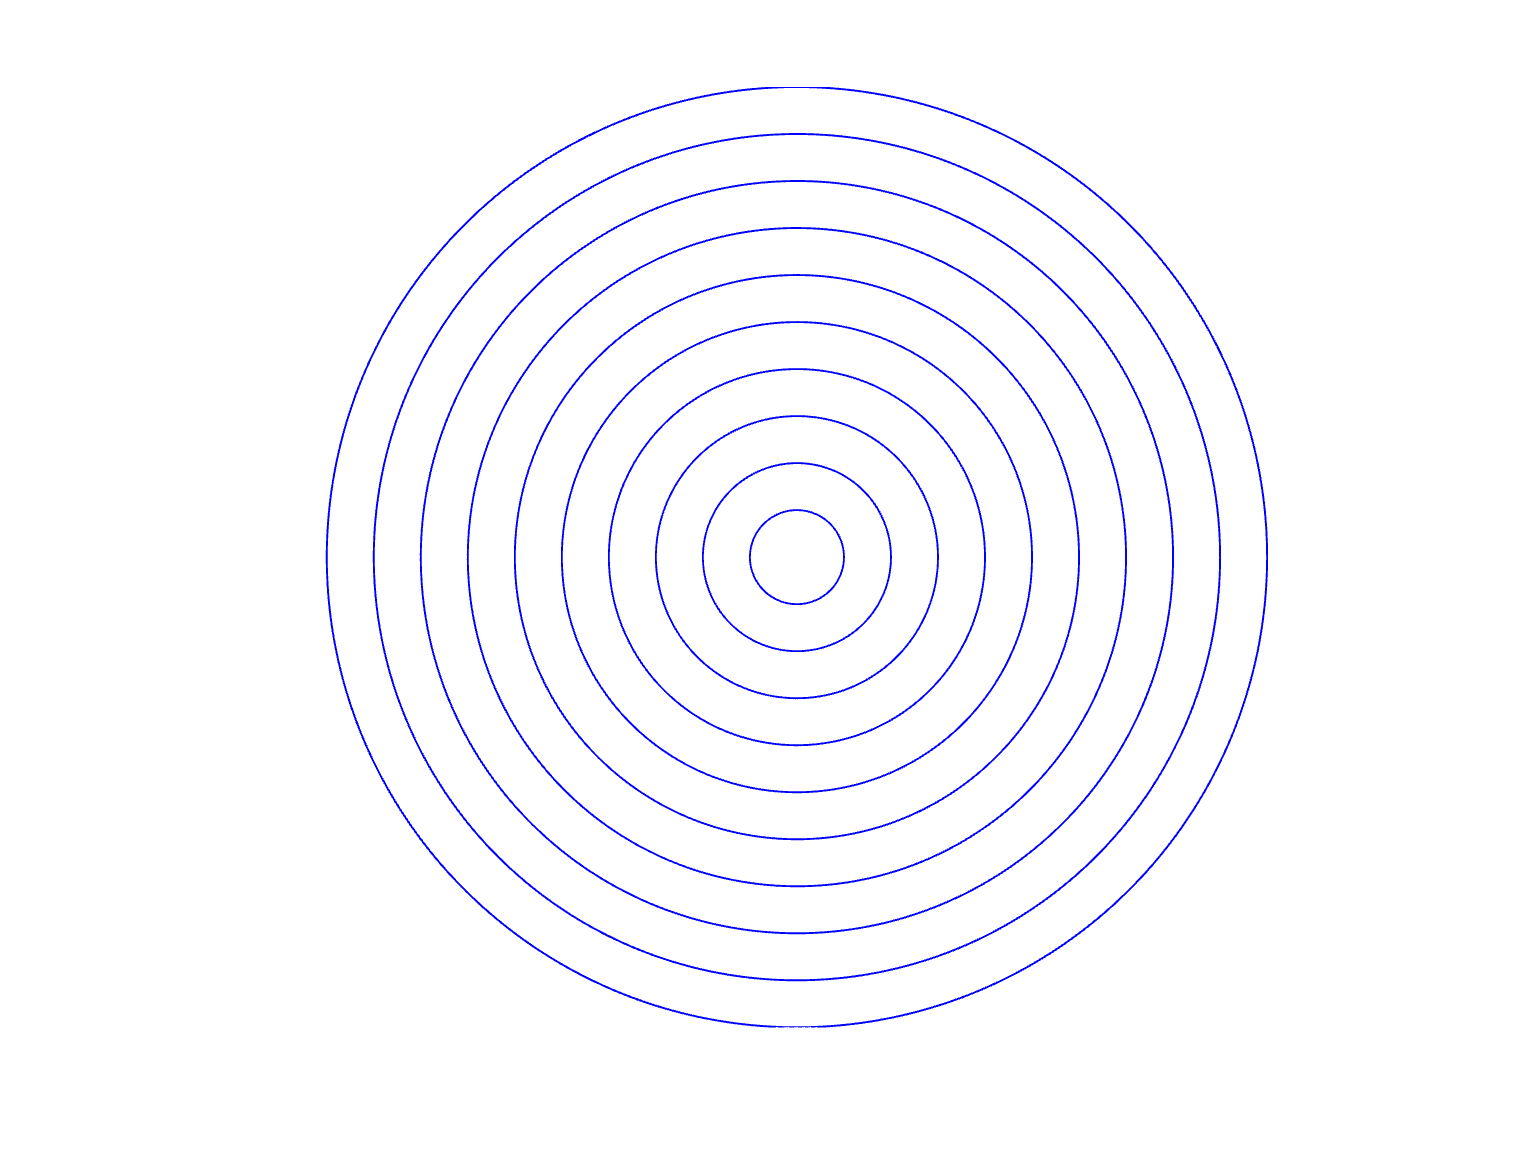

A=[cos(0.1) -sin(0.1); sin(0.1) cos(0.1)];
x0=[0:0.1:1.0; zeros(1,11)] ;
dt=0.5;
phase(A,dt,x0)

In this case, the eigenvalues are complex with an absolute values of 1:   $\lambda_1=\cos\Phi+i\sin\Phi=e^{i\Phi}$ and $\lambda_2=\cos\Phi-i\sin\Phi=e^{-i\Phi}$.    The eigenvectors, being complex, do not represent directions in "real" space.    The matrix $A$ and all its real powers are orthogonal; thus, it's action is to "push" the solutions around a circle of constant radius.

A plot of some of the phase curves for **Example III.3.3. **with$A=\rho\left[\matrix{\cos(\Phi) & -\sin(\Phi)\cr  \sin(\Phi) & \cos(\Phi)}\right]\qquad \rho=\frac{49}{50}\qquad \Phi=\frac1{5}\qquad{\bf x}_0=\left[\matrix{1\cr0}\right]$ is shown.

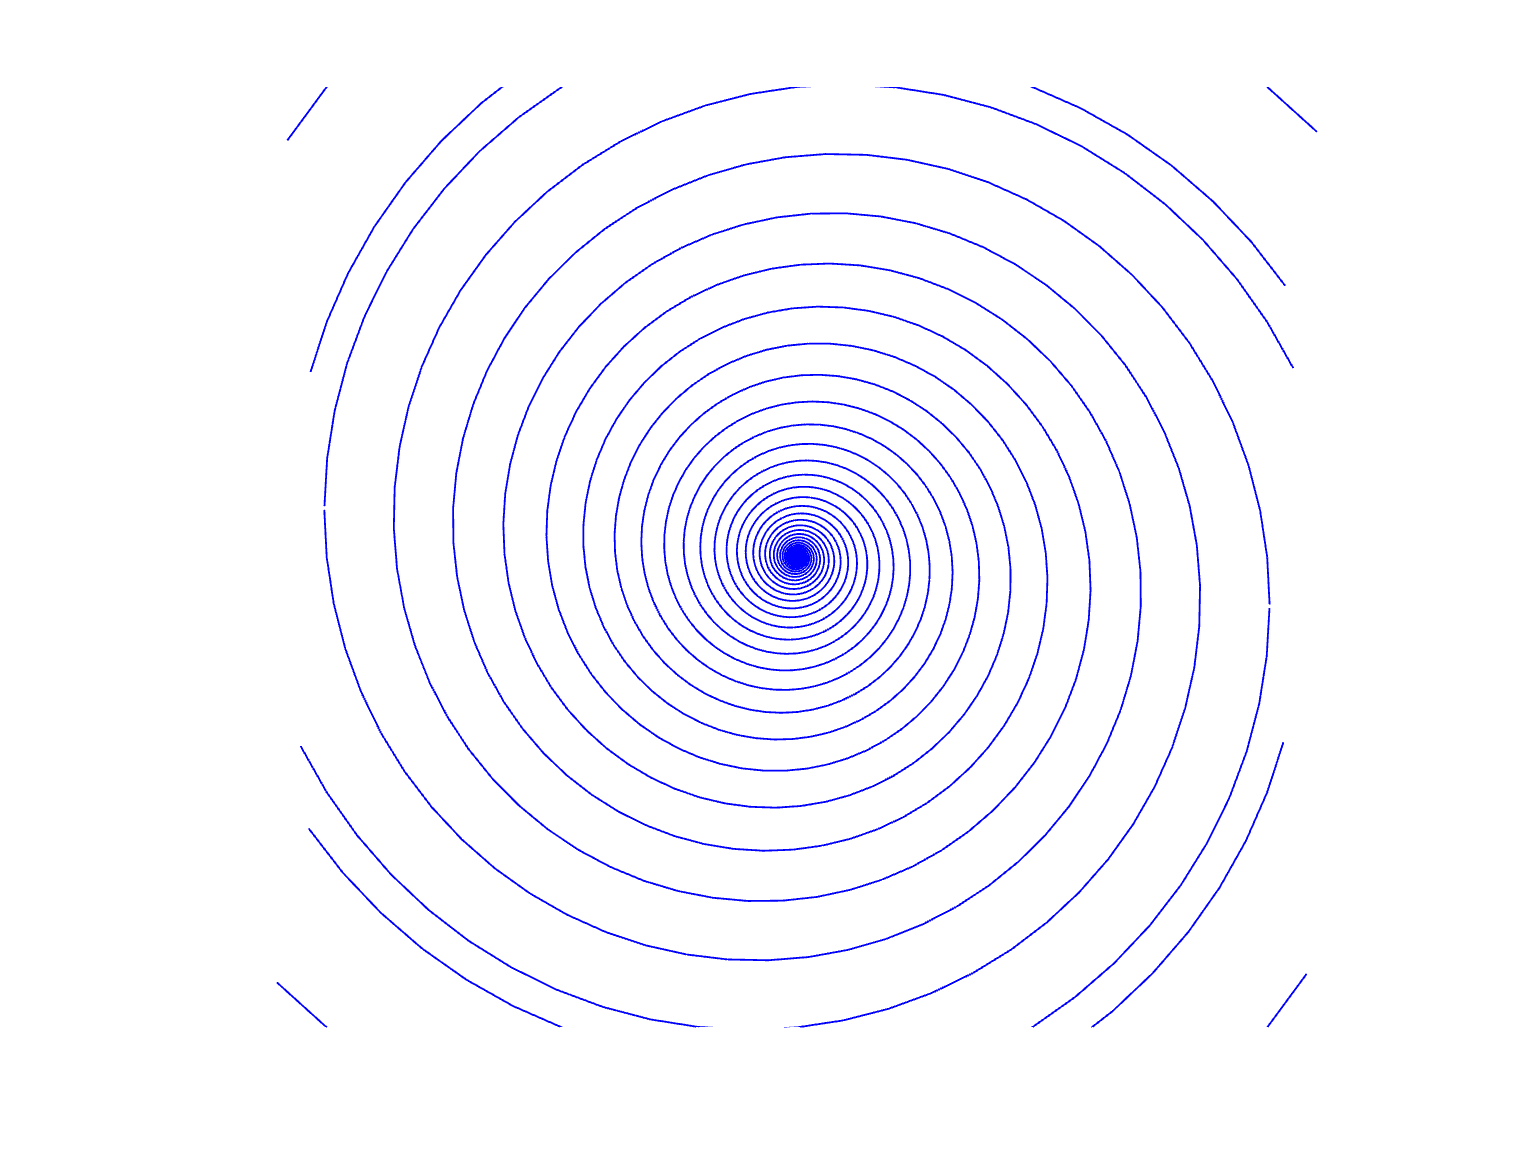

A=[0.98*[cos(0.2) -sin(0.2); sin(0.2) cos(0.2)]];
run=-1.0:1/2:1;
x0=[ [run; 1+0*run] [run; -1+0*run] [1+0*run; run] [-1+0*run; run]] ;
dt=0.5;
phase(A,dt,x0)

In this case, the eigenvalues are complex with an absolute value less than 1:   $\lambda_1=\rho(\cos\Phi+i\sin\Phi)=\rho e^{i\Phi}$ and $\lambda_2=\rho(\cos\Phi-i\sin\Phi)=\rho e^{-i\Phi}$. The eigenvectors, being complex, again do not represent directions in "real" space. The matrix $A$ is an orthogonal matrix scaled by $\rho\in(0,1)$; thus, the iterates spiral towards the origin.

A plot of some of the phase curves for the stochastic matrix of **Example III.3.4.    **$A=\left[ \matrix{\frac7{8} & \frac1{9}\cr \frac{1}{8} & \frac{8}{9}} \right] \qquad{\bf x}_0=\left[\matrix{1\cr0}\right]$.

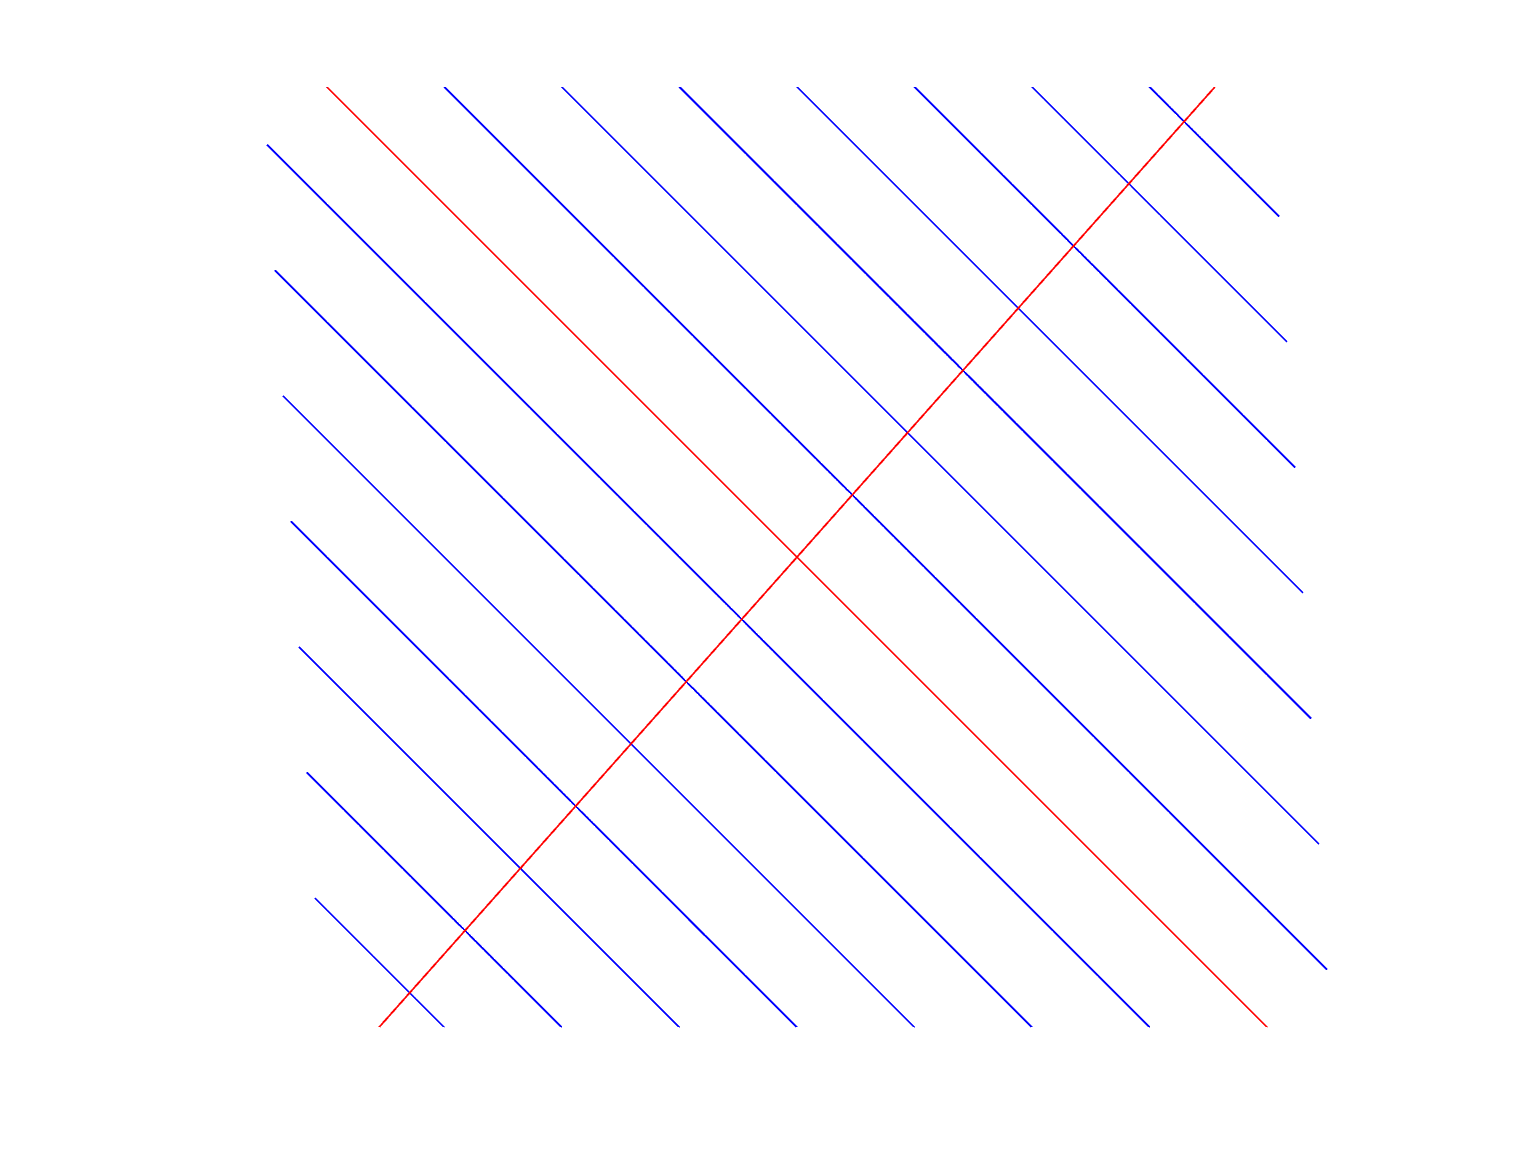

A=[7/8 1/9; 1/8 8/9];
run=-1.0:1/4:1;
x0=[ [run; 1+0*run] [run; -1+0*run] [1+0*run; run] [-1+0*run; run]] ;
dt=0.5;
phase(A,dt,x0)

Owing to the components of the columns of $A$adding to 1, the phase curves fall on affine sets where the components of each vector add to a constant.   The eigenvalues

eig(sym(A))

$$ans = \left(\begin{array}{c} \frac{55}{72}\\ 1 \end{array}\right)$$

show that $0<\lambda_1<1$ and $\lambda_2=1$.    Hence, $A^\ell {\bf x}_0=\lambda_1^\ell s_1{\bf v}_1+\lambda_^\ell s_2{\bf v}_2\to s_2{\bf v}_2$.

**Follow-up Problems**:

**Problem III.3.1:   **Suppose $a_{n+2}=\frac12 a_{n+1}+\frac12 a_n$.   Find$\lim_{n\to\infty} a_n$ in terms of $a_0$ and $a_1$.

**Problem III.3.2:**   Suppose $a_{n+2}= (1-\alpha) a_{n+1}+\alpha  a_n$.   Find$\lim_{n\to\infty} a_n$ in terms of $a_0$ and $a_1$.

**Problem III.3.3:   **Suppose $a_{n+3}=\frac13 a_{n+2}+\frac13 a_{n+1}+\frac13 a_n$.   Find$\lim_{n\to\infty} a_n$ in terms of $a_0$, $a_1$ and $a_2$.

**Problem III.3.4:   **Identify the absorbing states and steady distributions for each of the following transition matrices.


$$\qquad\text{(a)}\quad \left[\matrix{1/2 & 1/2\cr 1/2 & 1/2}\right]
\qquad\text{(b)}\quad \left[\matrix{9/10 & 1/2 \cr 1/10 & 1/2}\right]
\qquad\text{(c)}\quad \left[\matrix{1 & 1/2 \cr 0 & 1/2}\right]
\qquad\text{(d)}\quad \left[\matrix{1 & 0 \cr 0 & 1}\right]
$$



$$\qquad\text{(e)}\quad\left[\matrix{1/3 & 1/3 & 1/3\cr 1/3 & 1/3 & 1/3 \cr 1/3&1/3&1/3}\right]
\qquad\text{(f)}\quad\left[\matrix{1 & 0 & 0 \cr 0 & 1/2 & 1/2 \cr 0 & 1/2 & 1/2}\right]
\qquad\text{(g)}\quad\left[\matrix{0 & 1 & 0 \cr 0 & 0 & 1 \cr 1 & 0 & 0 \cr}\right]
\qquad\text{(h)}\quad\left[\matrix{1&0&0\cr 0&1&0\cr 0 &0&1}\right]$$



$$\qquad\text{(i)}\quad \left[\matrix{
2/3 & 1/3 & 0 & 0 &0 \cr 
1/3 & 2/3 & 0 & 0 & 0\cr
0&0&1&0&0\cr
0&0&0&4/5 & 2/5 \cr
0&0&0&1/5 & 3/5 \cr}\right]
\qquad\text{(h)}\quad \left[\matrix{1/2 & 0 &0 &0 &0\cr 1/2 & 1/2 &0 &0 &0 \cr 0 & 1/2 & 1/2 & 0 &0 \cr 0 & 0 & 1/2 & 1/2 & 0 \cr 0 & 0 &0 &1/2 & 1}\right]$$


**Problem III.3.5:**   Consider the Markov chain having seven four states and the transition matrix

$M=\left[\matrix{
0 &  1-a & 0 &0 \cr
1 & 0 &0 &0\cr
0&a&0&1\cr
0&0&1&0\cr

}\right]$        where    $0\le a\le 1.$

        (a)  Assuming that ${\bf p}_0=\left[\matrix{1&0&0&0}\right]^T$, find ${\bf p}_1,~{\bf p}_2,~{\bf p}_3,~{\bf p}_4,~{\bf p}_5$.

        (b)  Assuming that ${\bf p}_0=\left[\matrix{1&0&0&0}\right]^T$, find $\lim_{\ell\to\infty} {\bf p}_\ell.$

        (c)  What are the eigenvalues of $M$?

**Problem III.3.6:**  Consider the Markov chain having seven states and the transition matrix


$$M=\left[\matrix{
0&0&0&0&0&0&0\cr
1/3&0&0&0&0&0&0\cr
2/3&0&0&0&0&0&0\cr
0&1/3 &0&1&0&0&0\cr
0&2/3&0&0&1&0&0\cr
0&0&1/3 &0&0&1&0\cr
0&0&2/3&0&0&0&1\cr}\right]$$


        (a)  Identify the absorbing states of the Markov chain.

        (b)  Assuming that ${\bf p}_0=\left[\matrix{1&0&0&0&0&0&0}\right]^T$, find ${\bf p}_1,~{\bf p}_2,~{\bf p}_3,~{\bf p}_4,~{\bf p}_5$.

        (c)  Assuming that ${\bf p}_0=\left[\matrix{1&0&0&0&0&0&0}\right]^T$, find $\lim_{\ell\to\infty} {\bf p}_\ell.$

**Problem III.3.7*:  **Suppose that $M$ is a stochastic matrix and $P=\lim_{\ell\to\infty} M^\ell$.   Show that $P$ is a projection matrix.

**Problem III.3.8:**   For $A=\left[ \matrix{\frac7{8} & \frac1{9}\cr \frac{1}{8} & \frac{8}{9}} \right] $ find $P=\lim_{\ell\to\infty} A^\ell$.    What is $P^2$?

function ldseq(A,x,N)
    figure
    hold on
    markpoint(x,0)
    for ell=1:N
        x=A*x;
        if norm(x)>5
            break
        end
        markpoint(x,ell)
    end
end

function markpoint(x,ell)
    plot(x(1),x(2),'.k')
    string=strcat('${\bf x}_{',sprintf('%d',ell),'}$');
    text( x(1)+0.02, x(2) ,string, 'Interpreter','latex')
end

function figIII1a()
subplot(1,4,1)
hold on
title('${\cal S}_1$','Interpreter','latex','FontSize',16)
axis([-1 2 0 7])
axis off
plot([-1 2],[ 0 0],'k')
plot([0 0 1 1 0],[0 2 2 0 0],':g')
plot([0 0 1 1 0],[2 4 4 2 2],':g')
plot([0 0 1 1 0],[4 6 6 4 4],':g')
subplot(1,4,2)
hold on
title('${\cal S}_2$','Interpreter','latex','FontSize',16)
axis([-1 2 0 7])
axis off
plot([-1 2],[ 0 0],'k')
plot([0 0 1 1 0],[0 2 2 0 0],'g','LineWidth',6)
plot([0 0 1 1 0],[2 4 4 2 2],':g')
plot([0 0 1 1 0],[4 6 6 4 4],':g')
subplot(1,4,3)
hold on
title('${\cal S}_3$','Interpreter','latex','FontSize',16)
axis([-1 2 0 7])
axis off
plot([-1 2],[ 0 0],'k')
plot([0 0 1 1 0],[0 2 2 0 0],'g','LineWidth',6)
plot([0 0 1 1 0],[2 4 4 2 2],'g','LineWidth',6)
plot([0 0 1 1 0],[4 6 6 4 4],':g')
subplot(1,4,4)
hold on
title('${\cal S}_4$','Interpreter','latex','FontSize',16)
axis([-1 2 0 7])
axis off
plot([-1 2],[ 0 0],'k')
plot([0 0 1 1 0],[0 2 2 0 0],'g','LineWidth',6)
plot([0 0 1 1 0],[2 4 4 2 2],'g','LineWidth',6)
plot([0 0 1 1 0],[4 6 6 4 4],'g','LineWidth',6)
end

function figIII1b()
    figure
    hold on
    axis([-1.5 4.5 -0.2 0.4])
    axis equal
    axis off
    title('Graphical Representation of Block Stacking Transitions','FontSize',15)
    plot(0,0,'.k','markersize',16)
    text(0.1,0,'${\cal S}_1$','Interpreter','latex','FontSize',16)
    plot(1,0,'.k','markersize',16)
    text(1.1,0,'${\cal S}_2$','Interpreter','latex','FontSize',16)
    plot(2,0,'.k','markersize',16)
    text(2.1,0,'${\cal S}_3$','Interpreter','latex','FontSize',16)
    plot(3,0,'.k','markersize',16)
    text(3.1,0,'${\cal S}_4$','Interpreter','latex','FontSize',16)
    arc(1/2,0,1/2,pi,2*pi)
    ah(1/2,-1/2,0,pi/6,0.15)
    text(1/2-0.1,-1/2-0.2,'$p$','Interpreter','latex')
    arc(3/2,0,1/2,pi,2*pi)
    ah(3/2,-1/2,0,pi/6,0.15)
    text(3/2-0.1,-1/2-0.2,'$q$','Interpreter','latex')
    arc(5/2,0,1/2,pi,2*pi)
    ah(5/2,-1/2,0,pi/6,0.15)
    text(5/2-0.1,-1/2-0.2,'$r$','Interpreter','latex')
    arc(-1/2,0,1/2,0,2*pi)
    ah(-1,0,3*pi/2,pi/6,0.15)
    text(-1.65,0.1,'$1-p$','Interpreter','latex')
    arc(3.5,0,1/2,0,2*pi)
    ah(4,0,pi/2,pi/6,0.15)
    text(4.1,0,'$1$','Interpreter','latex')
    arc(1/2,0,1/2,0,pi)
    ah(1/2,1/2,pi,pi/6,0.15)
    text(1/2-0.2,1/2+0.15,'$1-q$','Interpreter','latex')
    arc(1,0,1,0,pi)
    ah(1,1,pi,pi/6,0.15)
    text(1-0.2,1+0.2,'$1-r$','Interpreter','latex')
end

function arc(x,y,r,theta1,theta2)
    theta=theta1:pi/90:theta2;
    X=x+r*cos(theta);
    Y=y+r*sin(theta);
    plot(X,Y,':k')
end

function ah(x,y,theta,dtheta,r)
    x1=x-r*cos(theta+dtheta);
    y1=y-r*sin(theta+dtheta);
    x2=x-r*cos(theta-dtheta);
    y2=y-r*sin(theta-dtheta);
    plot([x1 x x2],[y1 y y2],'k')
end

function figIII1c(instances,maxtime,M)
    for i=1:instances
        S=1;
        for time=0:maxtime
            subplot(instances+1,maxtime+1,1+time+(i-1)*(maxtime+1))
            plotstack(S)
            r=rand;
            if r<M(1,S)
                S=1;
            elseif r<M(1,S)+M(2,S)
                S=2;
            elseif r<M(1,S)+M(2,S)+M(3,S)
                S=3;
            else
                S=4;
            end
        end
    end
end

function plotstack(S)
    hold on
    axis([0 3 -0.1 6.1])
    axis equal
    axis off
    plot([0 3],[0 0],'k')
    if S==1 
        return
    end
    plot([1 1 2 2 1],[0 2 2 0 0],'g','LineWidth',1)
    if S==2
        return
    end
    plot([1 1 2 2 1],[2 4 4 2 2],'g','LineWidth',1)
    if S==3
        return
    end
    plot([1 1 2 2 1],[4 6 6 4 4],'g','LineWidth',1)
end

function figIII1d(M)
    figure
    hold on
    steps=100;
    axis([0 steps 0 1.2])
    p=[1;0;0;0];
    for ell = 0:steps
        plot(ell,p(1),'.r')
        plot(ell,p(2),'.g')
        plot(ell,p(3),'.b')
        plot(ell,p(4),'.k')
        p=M*p;
    end
    title('Evolution of the Probability Distribution among the States')
    subtitle('for a block-stacking process')
    xlabel('number of transitions')
    ylabel('probability of being in a state')
    legend('probability of ${\cal S}_1$','probability of ${\cal S}_2$','probability of ${\cal S}_3$','probability of ${\cal S}_4$','Interpreter','latex','FontSize',14,'Location','east')
end

function phase(A,dt,x0)
% plots phase curves for the iteration x(l+1)=A*x(l) for initial conditions
% given in x0 (each column of x0 is a different initial condition)
    [S,D]=eig(A);
    clf
    hold on
    L=1;
    maxcount=1000;
    axis([-L L -L L])
    axis equal
    axis off

    % general phase curves -- forward then backwards
    for x=x0
        b=inv(S)*x;
        t=0.0;
        clearvars xp
        for count=1:maxcount
            xp(:,count)=S*(D^t)*b;
            t=t+dt;
            if max( abs(xp(1,count)), abs(xp(2,count))) > L 
                break
            end
        end
        plot(xp(1,:),xp(2,:),'b')
    end
    for x=x0;
        b=inv(S)*x;
        t=0.0;
        clearvars xp
        for count=1:maxcount
            xp(:,count)=S*(D^t)*b;
            t=t-dt;
            if max( abs(xp(1,count)), abs(xp(2,count))) > L 
                break
            end
        end
        plot(xp(1,:),xp(2,:),'b')
    end

    % eigendirections
    if isreal(D)    % plot eigendirections only when eigenvectors are real
        for k=1:2
            v=S(:,k);
            if abs(v(1)) < abs(v(2))
                v=v*(L/v(2));
            else
                v=v*(L/v(1));
            end
            plot([v(1) -v(1)],[v(2) -v(2)],'r')
        end
    end
end
    
